# SQUIDLAB 2.9.4                                                                             

### Matt Coak, David Jarvis, Cheng Liu

### University of Birmingham, University of Warwick, University of Cambridge

### Nov 2025

## Licensing and fair use

SquidLab remains the intellectual property of the Universities of Warwick and Cambridge, but is freely distributed under an Academic Use license for non-commercial use. The license file is included with the code files when downloaded, and must always be kept with them if distributed. Please also credit the authors if the software contributes to any research results. Please read and make sure you agree with the points in the (short) license document. In brief, you may use and also modify any of the code files for non-commerical purposes, and should contact Warwick Ventures at the University of Warwick with any questions as to potential commercial or profit-making use. And remember, we can't guarantee that the software is bug or error free! Make sure to check any results.

## Overview

SquidLab is described in our paper:

M.J. Coak, C. Liu, D.M. Jarvis, S. Park, M.J. Cliffe and P.A. Goddard

*SquidLab - A user-friendly program for background subtraction and fitting of magnetization data*

Review of Scientific Instruments 91, 023901 (2020)

[http://www.doi.org/10.1063/1.5137820](http://www.doi.org/10.1063/1.5137820)

We ask that you cite this reference if SquidLab contributes to your research signifcantly. Thank you!

Firstly, please feel free to contact Matt Coak at m.j.coak@bham.ac.uk with:

- any technical difficulties or questions

- any suggestions for how to improve the programme, or potential applications or features we have not thought of

- reports of bugs, issues or annoyances

- suggestions on improving this manual or making SquidLab more accessible to use

- brilliant plugins, importers, or modifications to code you have made which you would like to share

- testimonials and gushing messages about how brilliant SquidLab is

SquidLab is a Matlab library for importing, analyzing and plotting scans taken from a SQUID magnetometer. It's designed to allow:

- Easy fitting of dipoles from raw V(z) voltage data.

- A unified import pipeline for the (often quite complex) raw scan data files.

- Fully-featured post-processing to resolve common issues with the raw data.

- Background subtraction of one scan from another.

- Fitting to the raw scans to obtain moment as a function of temperature or field.

It is built from the ground up around a plugin system. Any code files saved into the appropriate folders, with the correct format, will appear as options automatically in the programme. For instance, you can make a new Importer plugin if you have a dataset not covered by any of the included default plugins. The easiest way to do this, as with basically all programming tasks, is to make a copy of an exisiting one that is closest to the desired outcome and edit that.

SquidLab allows three methods of interaction with the underlying libraries:

- An interactive GUI to easily perform common tasks.

- A high-level "Actions" API for performing common tasks at the command line, which wraps the underlying classes and exposes a set of easy-to-use methods.

- The full low-level API, which makes extensive use of Matlab's OOP capabilities to provide a highly extensible framework for analyzing SQUID data.

At first, you will almost certainly use the GUI - and in most cases you will always use the GUI. For batch processing large amounts of data, the command line tools may become your friend.

We hope that SquidLab will be as helpful to you and your research as it has proved to us!

## Before even thinking about using SquidLab - notes on performing the measurements

The Quantum Design Magnetic Property Measurement System (we support other instruments too, but this is the most common so let us focus on it) is a very sensitive instrument for measuring magnetic properties based on the SQUID magnetometer. However, sometimes for magnetically dilute samples or bulky sample holders and environments, their magnetic response can be so weak that it is comparable to the response from the sample holder used. The fitting algorithm employed by the MultiVu software for obtaining the magnetic moment can become unreliable in such cases (gets trapped in local minima, or the data no longer resemble the assumed dipole etc), and even the subtraction of the fitted background moment from the fitted sample+background moment does not result in a satisfactory outcome. In such cases, it becomes necessary to work directly with the SQUID voltages vs position data of the [sample + background] and [background] in order to recover the magnetic response due to the sample only and fit that to obtain meaningful information about the magnetic moment of the sample.

It is always important and easier to minimise the measurement background from the outset. This can mean the choice of sample holders that give the minimal background signal - such as the quartz-paddle sample holder, or the straw sample holder. The quartz-paddle sample holder can be used throughout the entire temperature range of the standard MPMS3, i.e. 1.8K to 400 K, while the straw can be used for temperatures from 1.8K to about 350K as long as it is straight.

*In an MPMS3 equipped with the VSM option, background subtraction can be very simple. Simply measure the sample holder (manually centre at 66mm), and the sample holder plus sample, using the exact same sequence. Care should be taken to ensure everything is placed in the same position. Then, subtract one from the other - (moment[sample+background]-moment[background]). This generally works very well. This is because for the VSM measurement, the sample is oscillating with a small amplitude in the middle of the detection coils. A lock-in amplifier (looking at the 2nd harmonic) then measures the induced voltage, which is in-turn proportional to the magnetic moment via calibrations. Consequently, there is no complicated curve-fitting or waveforms involved, making the procedure very straightforward.*

Make measurements of the [sample + background] and [background] using the exact same sequences, recording raw data in the measurement setup. Particular care should be taken to ensure the various parts of the sample holder (including capsules for powder samples, tape, quartz cylinders etc) are placed at the exact same positions. Make sure that magnetic history, trapped and remnant field in the cryostat are the same across both measurements. Sweep temperatures at the same rate to ensure the same thermalisation. SquidLab will interpolate between differing field, position and temperature values - but it is cleanest and safest to minimise the amount we rely on this, especially for noisy data where interpolants can get rather chaotic.

More data points in each scan is good, and longer scan lengths are good - in particular long scans can allow identifying features in the background which can be matched between scans to verify offsets. Consider measuring a single scan over the full available length before each measurement and recording that - as a later verification check. However... for very very small signals, a low number of points will minimise mechanical vibration (in an MPMS1) and so give better results - there is no simple answer to all this!

Useful references are the MPMS Application Notes from Quantum Design - eg 'Application Note 1014-213 - Subtracting the Sample Holder Background from Dilute Samples'.

## Before you start - setup and requirements

You will need Matlab version R2020b or later, with the `Curve Fitting Toolbox` and the `Statistics and Machine Learning Toolbox` installed. The programme should work on Macs, but has not been extensively tested. If you do not have the correct version, or the required toolboxes, you will be greeted by error messages on startup.

Installation means simply copying the SquidLab folder into whatever location you find convenient on your PC. Be careful to preserve the directory structure and names however - things like '+squidlab' are how Matlab handles namespaces in the code, to keep calls like eg 'squidlab.Actions' distinct from any Actions.m code the user may already have written. 

The only thing you should need to do is to add the SquidLab folder, and sub-folders, to the Matlab Path. This Path is a list of folders Matlab keeps stored, in which it will look for code files corresponding to commands you enter. Ie, if you type 'SquidLab' into Matlab, it does not look for something called that on your whole PC, only in its list of folders. Check Matlab online documentation for 'setpath' or 'savepath' for more info.

I have added the SquidLab folder to my path, and also for good measure have placed it in my working directory:

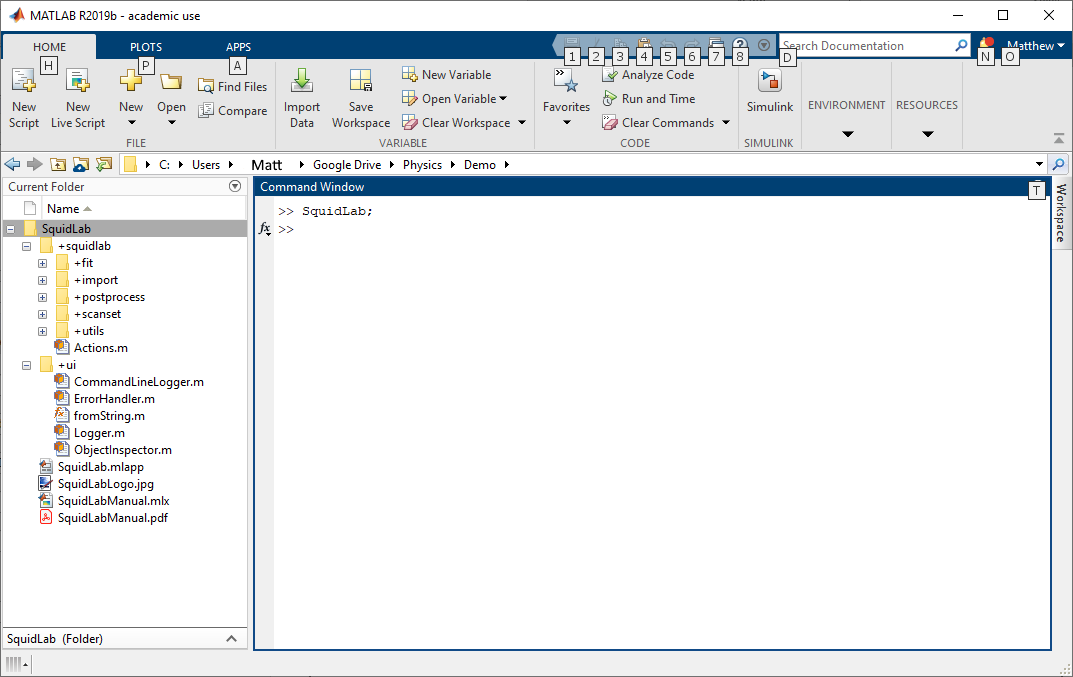

If you are having trouble getting SquidLab to launch, get your Matlab enviroment to look like this! Because SquidLab is on my path, the folders are not greyed out/translucent. To get them on there, right click the parent 'SquidLab' folder icon on the left, and choose 'Add to Path > Folders and subfolders'. There is also a 'Set Path' menu in the ENVIRONMENT menu shown top-right in this image. After setting the path, one can, if Matlab is behaving itself, enter the command 'savepath' to save this for next time in the command window, and hit enter.

*A tip for power users / troubleshooting* - the file ErrorHandler.m, which controls how SquidLab deals with errors and warnings, has the line: 

 DebugMode = false;   %Set to true to rethrow all handled errors and hence have a stack trace to follow in the command window - for debugging/testing purposes 

.. at the top. Change the `false `to `true` and Matlab will rethrow all errors into the command window with full stack trace, rather than using the more user-friendly and simple SquidLab error boxes, making diagnosing complex bugs easier.

## Using the SquidLab GUI

###     Launching and configuring the GUI

If everything is set up properly and SquidLab is on the Matlab path, you can launch it by double-clicking the SquidLab.mlapp file, inside or outside of Matlab, or by entering:

Into the command window, as in the previous screenshot. The first time you do this, it is worth checking the command window afterwards for any warnings or errors it may print out!

Here is what you should see, immediately after launching SquidLab (note that newer versions may look a little different):

## 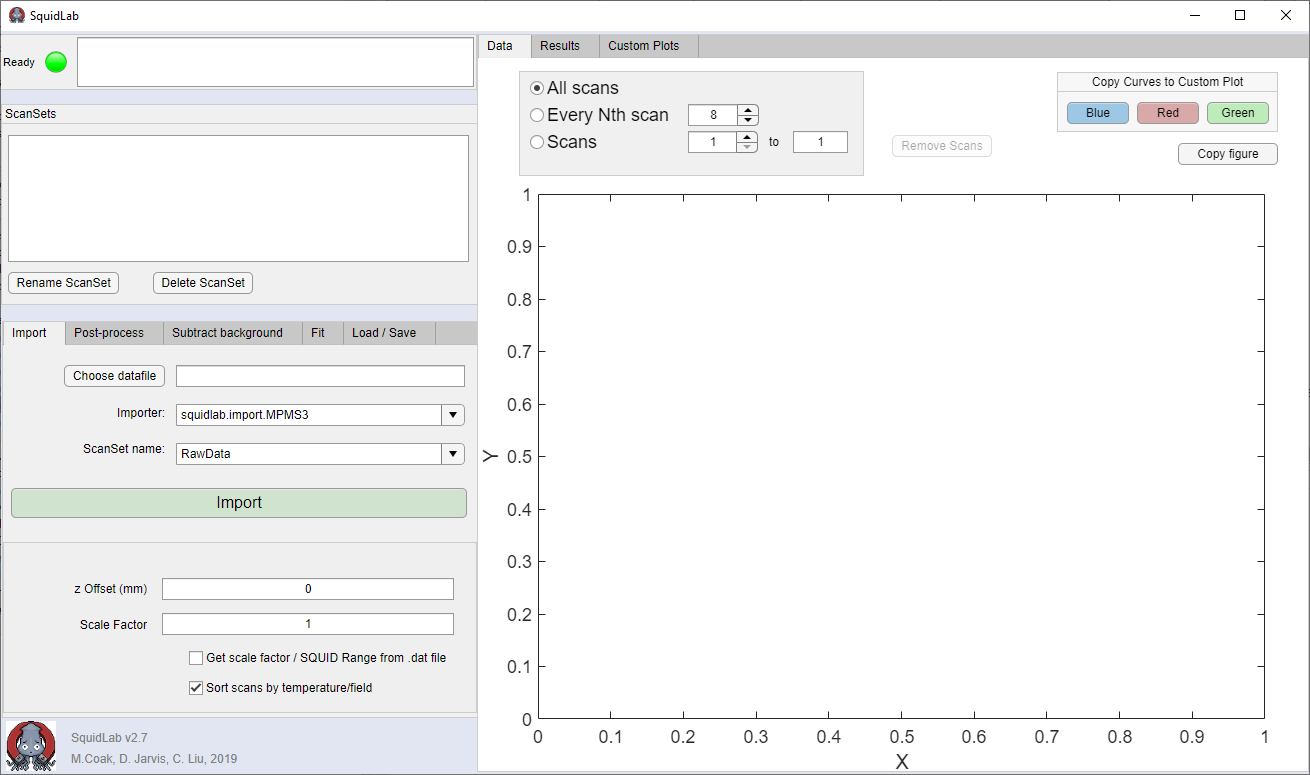

Note the green 'Ready' lamp in the top left. If this is red and reporting errors, things have gone wrong - hopefully the error messages will give you clues as to what!

If you wish to make modifications to the GUI, the SquidLab.mlapp file which defines it can be opened in Matlab's App Designer environment, by entering 'appdesigner' into the command window then selecting to open 'SquidLab.mlapp'. It should have a design view for laying out controls and tweaking properties, and a code view like this:

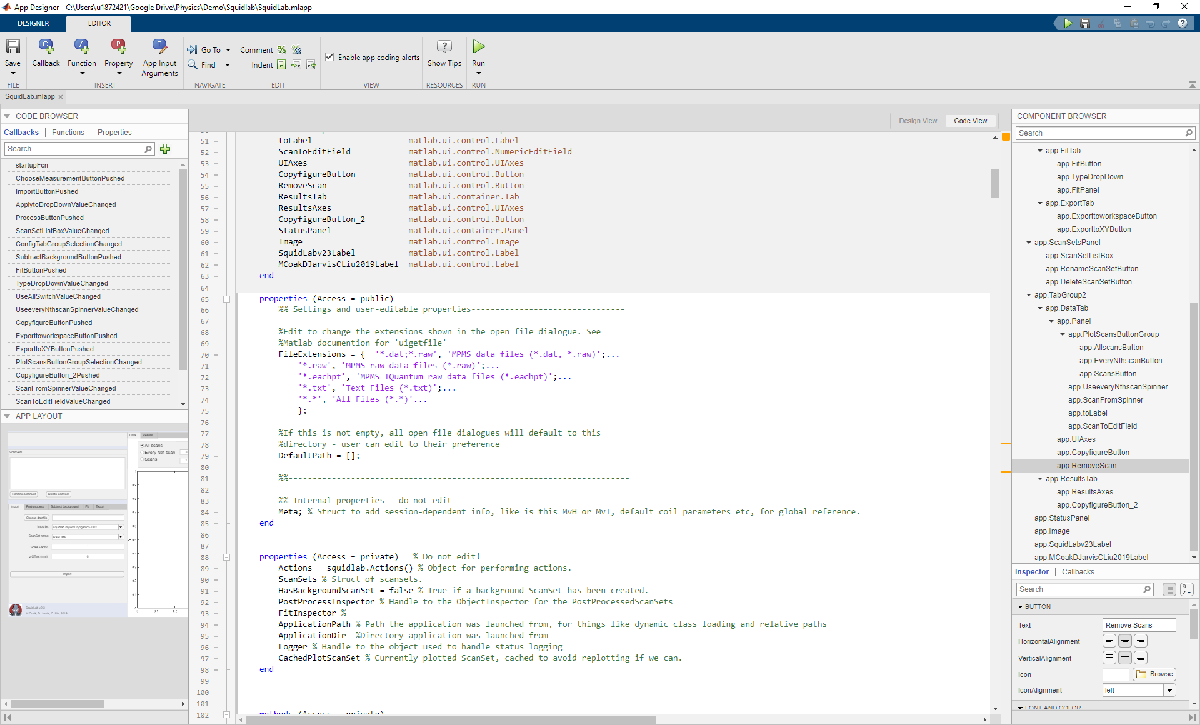

You are very welcome, within the terms of the licence to make any modifications to this you desire - but we would ask that the logo and author names are left intact.

Worth noting here are the user-specified properties near the top:

 properties (Access = public)
    %% Settings and user-editable properties--------------------------------
    
    %Edit to change the extensions shown in the open file dialogue. See
    %Matlab documention for 'uigetfile'
    FileExtensions = {  '*.dat;*.raw', 'MPMS data files (*.dat, *.raw)';...
        '*.raw', 'MPMS raw data files (*.raw)';...
        '*.eachpt', 'MPMS IQuantum raw data files (*.eachpt)';...
        '*.txt', 'Text Files (*.txt)';...
        '*.*', 'All Files (*.*)'...
        };
    
    %If this is not empty, all open file dialogues will default to this
    %directory - user can edit to their preference
    DefaultPath = [];
    
    %%-----------------------------------------------------------------------
    
    %% Internal properties - do not edit
    Meta;   % Struct to add session-dependent info, like is this MvH or MvT, 
            % default coil parameters etc, for global reference.
end

If implementing new Importers, you can add more supported file extensions for the Browse File dialogue boxes to FileExtensions (in this format, see the Matlab online help for uigetfile). And very much worth doing is to set the DefaultPath property, eg:

DefaultPath = 'C:\Users\Matt\Google Drive\Physics\Data\SQUID\';

so the dialogue boxes will open in a more useful starting folder, rather than the default Matlab directory.

### Example analysis using the SquidLab GUI

This section talks you through step-by-step a 'typical' data import, processing and subtraction operation for MPMS data in the SquidLab GUI. This is far from restrictive however! You can run any number of the steps, in any order. For instance, you can load in a RawData ScanSet then immediately fit it with no background subtraction, or you can perform subtraction before the smoothing step, etc etc..

*    There are 2 sets of data included in the folder 'Example Data' bundled with your SquidLab download - for you to practice on. At the end of this section you can find the instructions and example results to reproduce for these.  *

The steps we will generally take are:

- Import a RawData set

- Import a BackgroundData set

- Post-process the RawData

- Post-process the BackgroundData

- Subtract the PostProcessedBackgroundData from the PostProcessedRawData

- Fit the subtracted data to a dipole form

- Export the resulting moment vs temperature/field to file if desired

These flow from left to right as the Import->Post-process->Subtract background->Fit->Export tabs on the left panel. Selecting each of these will show dynamically-loaded properties and documentation for each process. Then a button on each will apply the specified operation and make the output ScanSet.

SquidLab bundles data into what we call a ScanSet - a list of scans at different temperatures or fields. Each 'scan' is a list of voltages against positions. When any operation is carried out, a new ScanSet is created, automatically named with a descriptive title and added to the list of available ScanSets:

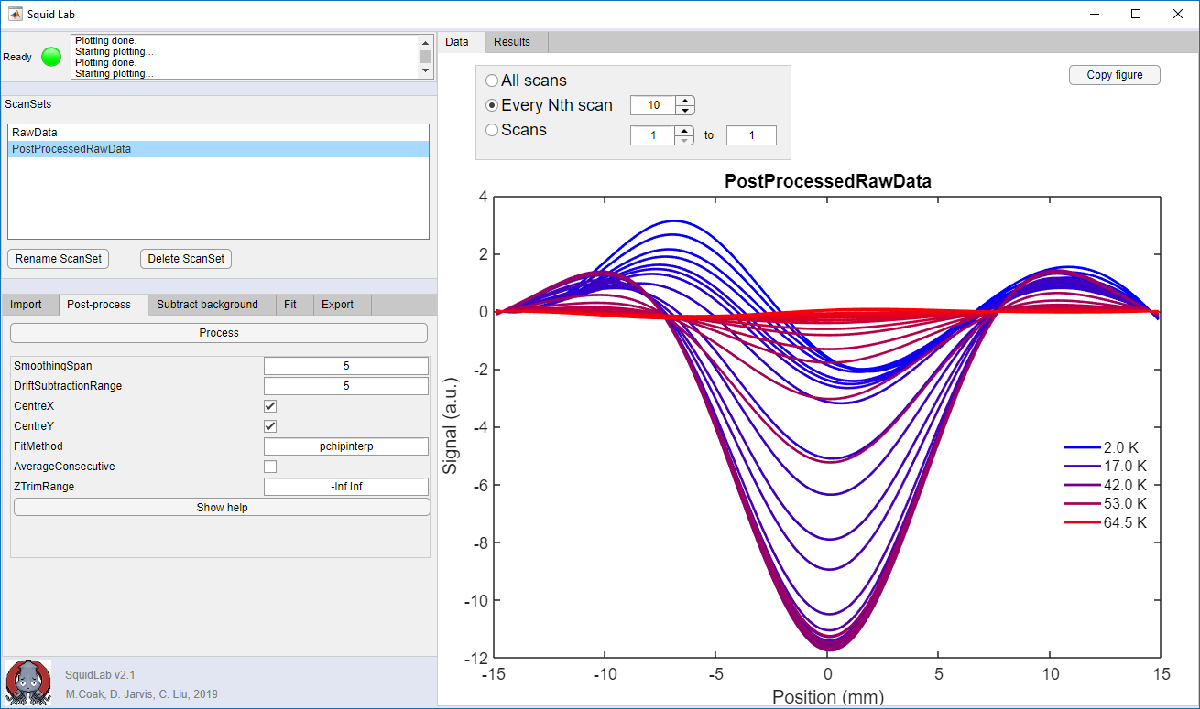

Here, the ScanSets box in the top-left has a RawData and a PostProcessedRawData entry - the latter is selected and hence plotted on the Data Axes to the right. Selected ScanSets can be deleted or renamed by the buttons below the ScanSets list. 

A plotting options box above the Data Axes allows selecting to plot certain subsets of scans. If the Scans, x to y, option is selected, a Remove Scans button will become enabled, and the currently plotted scans will be removed from the current ScanSet. Use this if there is loads of noise at one anomalous temperature, or some isolated jumps in the data in a few scans, etc. Please note that SquidLab will not modify the input files, or indeed write to any files outside the Export tab's operations - your data are safe! 

A handy little Copy Figure button in the top right will pop out a new figure of the currently plotted data, to save for later, print for your log book or similar. Note that in this new version of Matlab, zoom and panning controls for axes are found by moving the cursor near the top right of the axes, making some little icons appear for these options.

#### 1 and 2 - importing data

We begin! On the Import tab:

begin by clicking 'Choose datafile'. This will open a dialogue box to browse for the file to import:

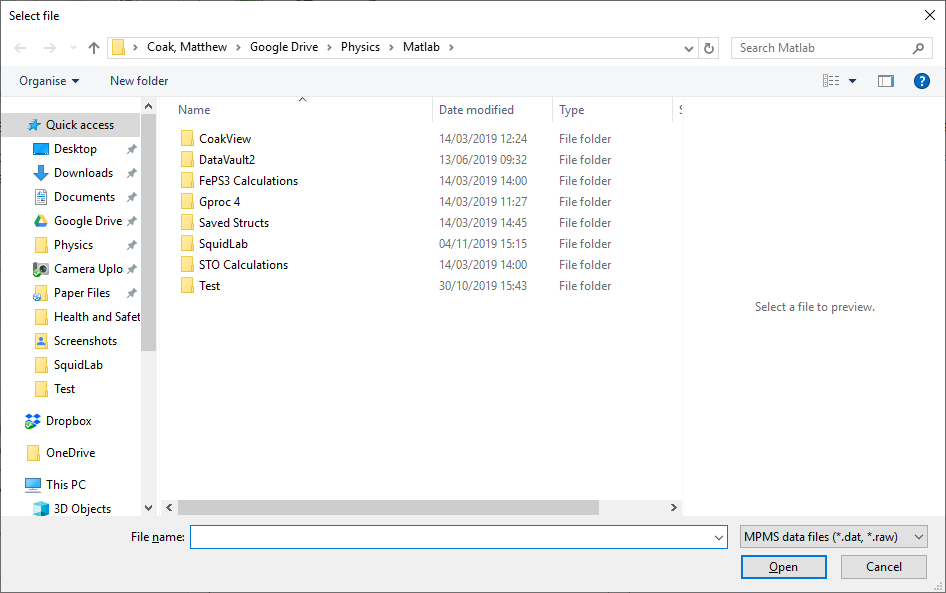

If it's MPMS or MPMS3 data, don't forget to select the raw file! Eg 'blahblah.raw.dat'. It is the full voltage vs position data we are after. Note that there is a drop-down selection box in the bottom right where you may filter by file types - select the appropriate extension for your files (eg MPMS I-Quantum Helium-3 files have an .eachpt extension and so will not initially show up). Hit open, and the box next to 'Choose datafile' should populate:

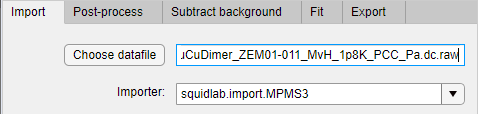

Next, make sure the appropriate Importer is selected in the next box down. These data were moment vs field ('MvH') at a fixed temperature, on an MPMS, so I will select 'squidlab.import.MPMSXL_MvH' from that drop-down. Thre is a section later in this manual listing what all the Importers bundled with SquidLab are for, and hence which to choose. And of course you can write your own (seriously, you really can)! 

ScanSet name has two defaults to choose from, 'RawData' and 'BackgroundData' - but you can also simply type in the box to name the ScanSet whatever you wish (though it must be a valid Matlab name! Avoid spaces and silly symbols!). These are raw data, so I will simply leave this as 'RawData'.

*OPTIONAL - The Advanced panel - Scale Factor and z Offset boxes and the Get Scale Factor checkbox are for advanced users only, we can ignore these for now. Scale Factor will multiply the voltages by its value - hence the default 1. This is mainly used when a bug on certain MPMS3 models emerges. In some versions of the software, the MPMS3 records its voltage 'squidrange' parameter as its maximum value of 1000, but only in the .raw file, not the resulting .dat. This is a confirmed bug from Quantum Design and there is nothing SquidLab can do about it. SquidLab will give you a warning:*

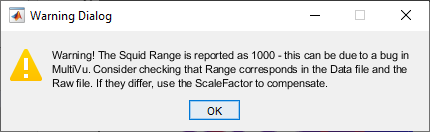

*but will merrily carry on otherwise. If you see this warning message, open your .dat and .raw files and make sure that the Squid Range numbers correspond. The .dat will be correct. If the .raw is wrong, compensate using Scale Factor to get the data to the correct magnitude (or your final resulting moment from fits will be 1000 times too big for example). You can check the Get Squid Range from .dat File checkbox to have SquidLab open the .dat file for you and apply the correct ranges. Only do this if you do indeed have the 1000 bug however! *

*z Offset is for use in adjusting data that are not identically centred - ie the background data are at slightly different physical positions than the raw. This will shift all the positions (ie shift the graphs left or right) during import. This can be very useful in matching up slightly misaligned, and large, backgrounds. NOTE however, that the CentreX option in Post-process will merrily undo all this hard work by shifting the data back to be centred on 0! So be careful to avoid ticking CentreX until after subtracting background if one of your data sets is offset.*

*The checkbox to sort by temperature/field will do.. exactly that. If unticked, scans will be displayed in the order they appear in the data file. If it's ticked, they will be ordered by T, if an MvT sweep, or H, if an MvH magnetic field sweep at fixed temperature. This will not impact final results, merely how plots appear within SquidLab. *

Now that we have all the Import parameters just so and in shipshape order, we can hit Import at the bottom to load the data into a standard ScanSet item. We will either get an error message, which probably means you selected the wrong importer, or something that looks like this:

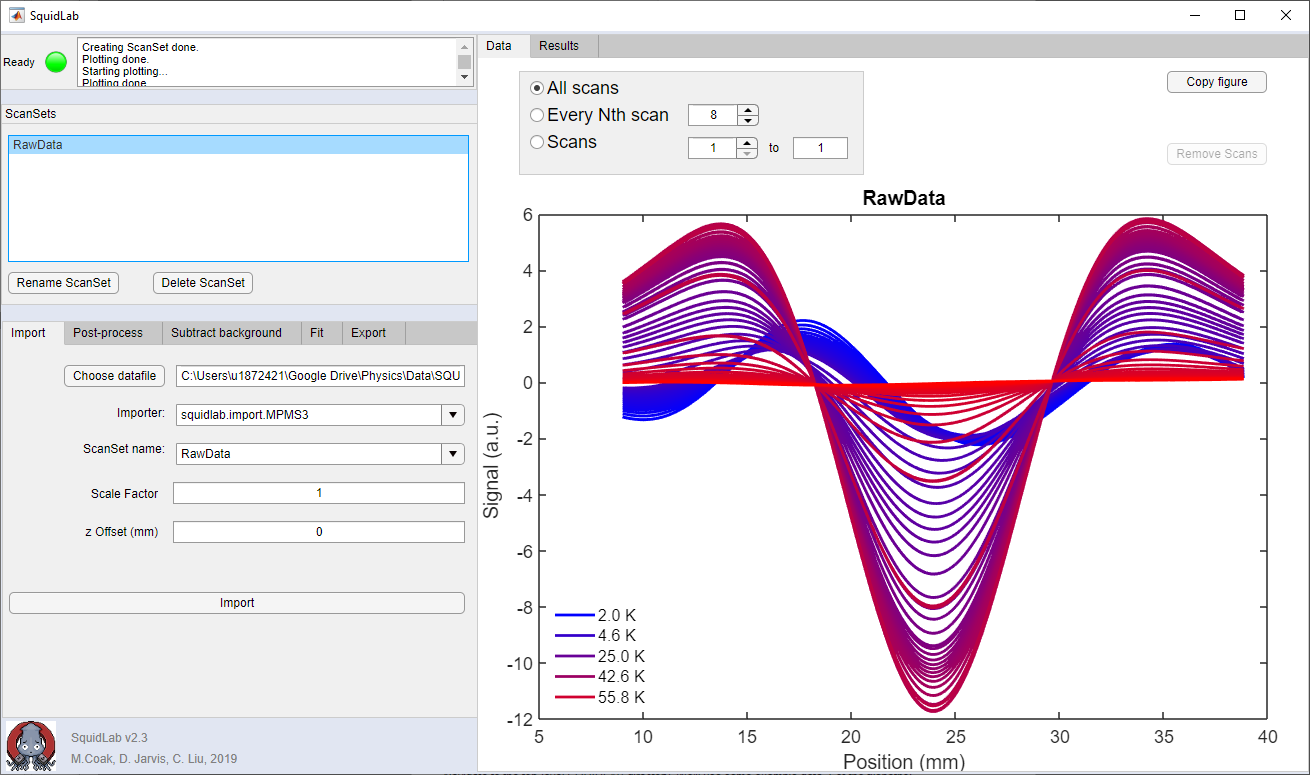

- the raw data are shown plotted in the Data Axes. Check that we have MvT or MvH correct here - you can see that the data are labelled from 2.0 K to 55.0 K. If they were all labelled '1000 Oe' we might suspect we had an MvH importer selected by mistake!

Now we repeat the same steps, but selecting the background data file and changing the ScanSet name to BackgroundData, giving us:

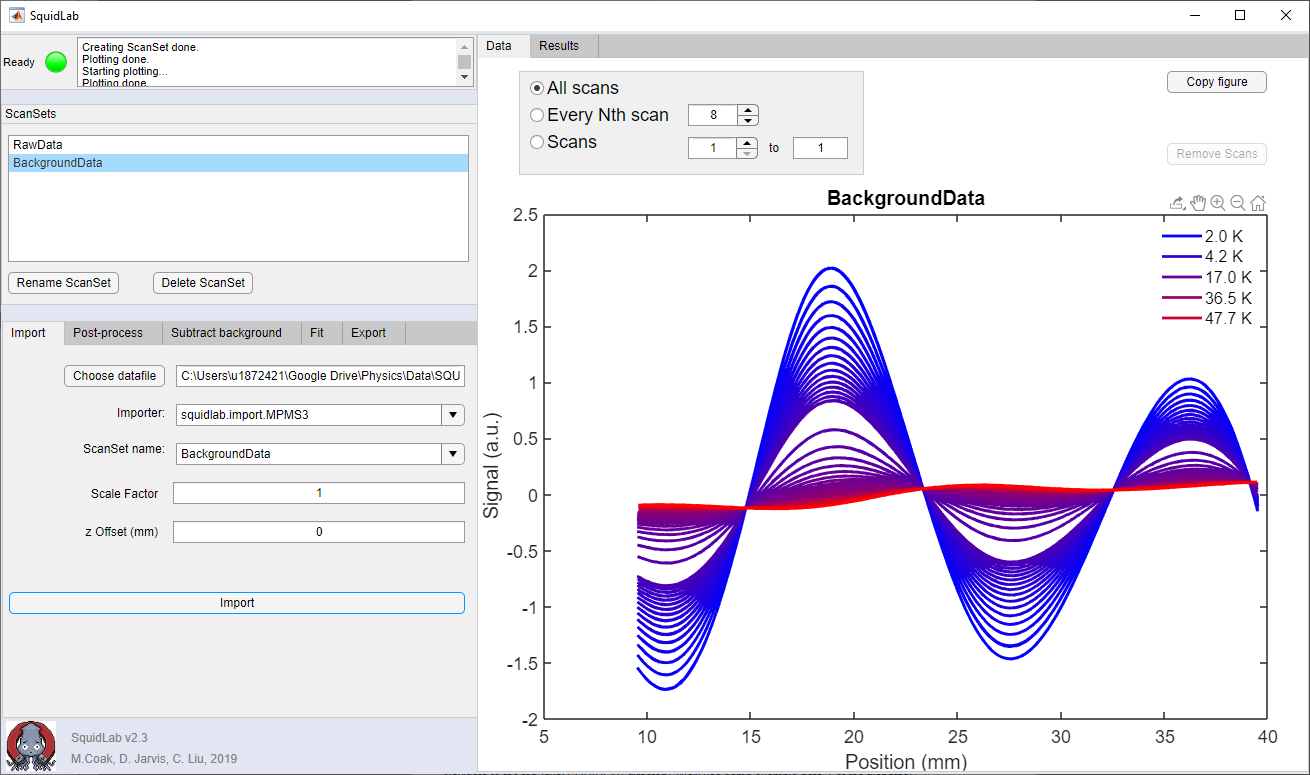

We have a RawData and a BackgroundData ScanSet imported and shown in the list. Next step now!

#### 3 and 4 - Post-processing the data and background

The next step is to apply some processing to the data, both raw and background. In some scenarios it can be better to perform this after subtraction (step 5), and the best options to select will depend heavily on the signal and the instrument it was taken on - look at and think about the data produced! The defaults were written with an MPMS3 in mind:

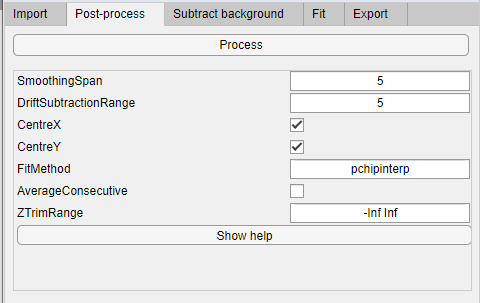

and here is an updated screenshot from v2.7, where the defaults are more sensible for an MPMSXL: 

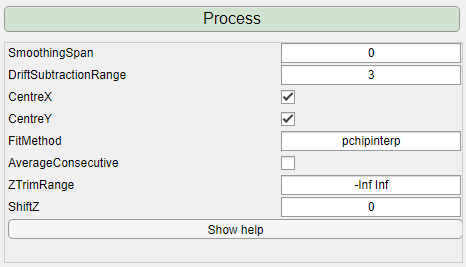

*Note for the enthusiast: these defaults can be changed by editing the* `PostProcessedScanSet.m` *file, in the* `+scanset` *folder*:

properties(Access = public)
        % SmoothingSpan (scalar odd int)
        % Sets the size of the moving average window used by smooth() to
        % smooth data (a larger value will mean more smoothing).
        % Value of 0 will leave data unchanged.
        SmoothingSpan = 0;
        
        % DriftSubtractionRange (scalar int)
        % Sets how many points are used at the start and end of a scan to
        % subtract a linear drift. If this is 5, a straight line will be
        % fitted to the first 5 and last 5 points, and this straight line
        % will be subtracted from the signal.
        % Value of 0 will leave data unchanged.
        DriftSubtractionRange = 1;

One all the options are specified as desired, hit Process at the top to apply all selected operations and create a PostProcessed ScanSet:

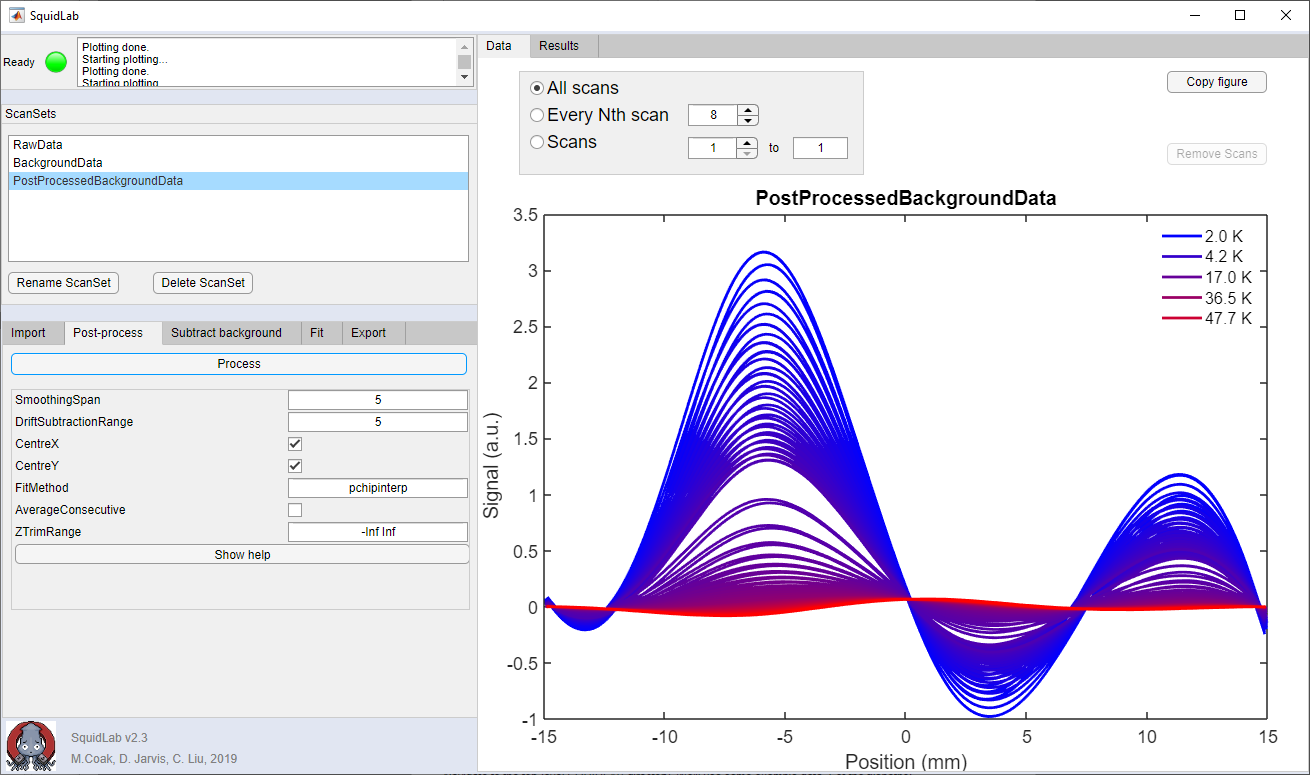

These data are the same as in the previous screenshot, but have been smoothed (not really neccesary in this example), a linear drift subtracted, and the data centred around x=0 and y=0. The parameters in detail (each has clear tooltips when hovered over to give help):

- Smoothing span - either 0 (off) or number of points in smoothing window. Beware using this on older model MPMS data where there can be only 24 data points!

- Drift subtraction range - either 0 (off) or number of points at start or end to fit linear trend to for subtracting linear voltage drift. MPMS instruments do this internally to all final data. SQUID coil voltages drift over time, this corrects for this linear drift.

- CentreX - Will centre the data around Position (x) = 0 if selected. This is applied after the ZTrim operation, if applicable. Strongly reccomended before running a fit - fits will struggle to converge on dipoles far from 0. *NOTE  - if you previously used a z-offset, do not use CentreX until after background subtraction*

- CentreY - Will centre the data around Voltage (y) = 0 if selected. Not hugely impactful, Drift subtraction really has this covered in most cases.

- FitMethod - 'none' or 'pchipinterp' or other options for 'fit()' (tip: just leave this alone!). Sets how the scan is fitted and replaced. Use this to improve smoothing. If this is "none", no replacement will be done. If this is e.g. "pchipinterp", the sweep will be replaced with a cubic interpolating spline. See options for fit().

- AverageConsecutive - Sets whether every pair of scans is averaged. You want this if the import process splits up and down scans. In this case, you want to average these two together - This is for certain MPMS3 files mostly, try this if you have unexplained duplicate data points.

- ZTrimRange - you can specify Position values to trim the data between, if you wish to exclude parts of the scans. Eg '-Inf 10'.

- ShiftZ - same as the equivalent option on the Import tab, this will shift the ScanSet to the right (if positive) to compensate if the Squid sample rod was a slightly different length between measurements or similar issue. CentreX will undo your hard z-shifting work though, be aware!

We repeat the same steps for the RawData and BackgroundData, to give us PostProcessedRawData and PostProcessedBackgroundData ScanSets in the list. To Process another ScanSet like this, select it in the ScanSet list, so it is plotted in the axes, then hit Process.

#### Background subtraction

Arguably the most important step! But nice and simple. I select PostProcessedRawData and PostProcessedBackgroundData as below:

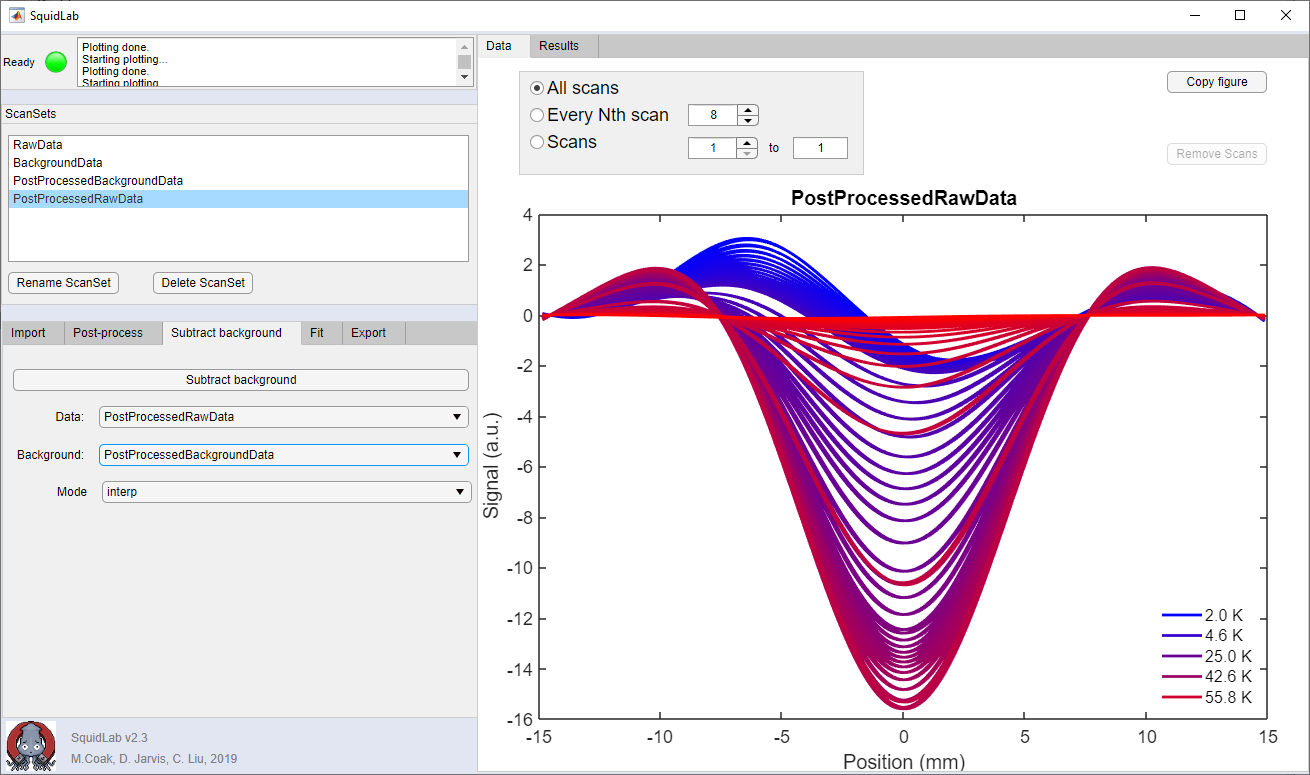

... and hit Subtract background. Note that for this case, it does not matter what ScanSet is currently selected -  it works only on the ones specified in Data and Background on this tab. You can choose between 2 subtraction modes. Nearest will simply take background points as close as possible to raw data points (close in temperature/field and in position) and use them. 'Interp' will create a 3D interpolant of each data surface and then sample from that. In general this is much better! But quickly-varying or noisy data may lead to misleading interpolation and Nearest then becomes required. 

With a bit of luck, you will end up with textbook dipole shapes (showing only scans 80 to 100 here for clarity):

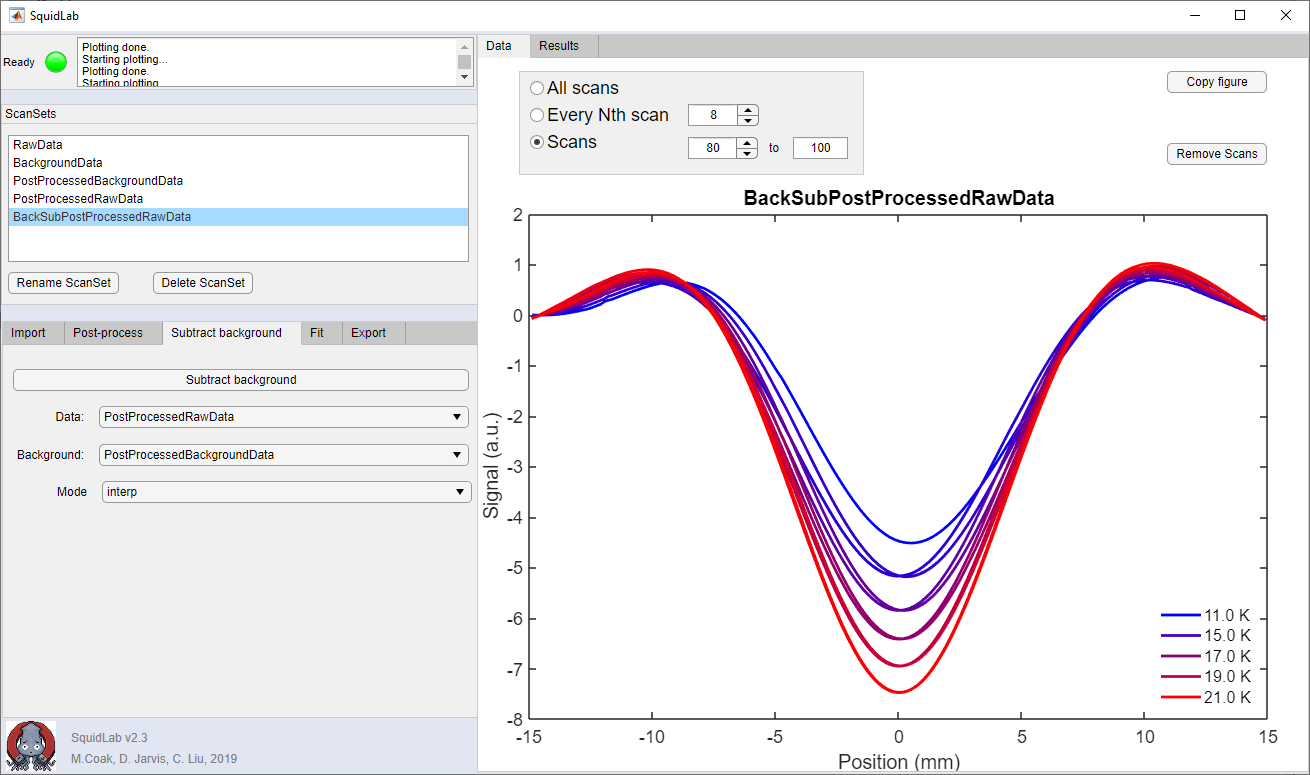

#### 6 - Fit

We should at this point have a dipole we are happy with, with the background removed, and ready to fit. We can of course run as many additional PostProcessing steps as we like first too. Note in particular that the fits will struggle if the dipole is not at or near z-Position = 0.

There are 2 fitting methods included by default with SquidLab, and as with the Importer plugins, you can make more alternatives (though these are more involved). The two defaults are the Levenberg-Marquadt and SVD (Singular Value Decomposition):

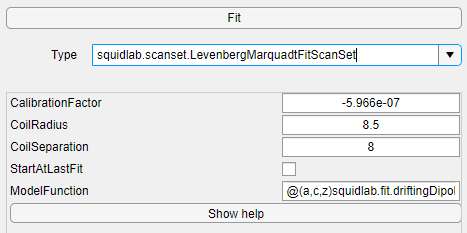

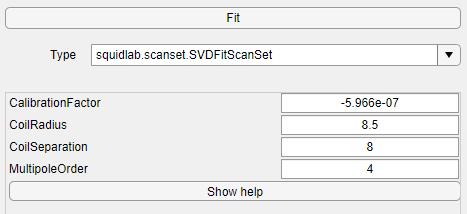

Note that both have Calibration and geometric factors relating to the magnetometer used. These are specified in the Importer file, and hence should be automatically populated with the correct defaults. Values like these can be found from you instrument's documentation, contacting the manufacturer, or by running eg palladium reference sample measurements. The values given in the bundled Importer plugins should be fine, but your MPMS may be 1% different for example. Again, we are not going to take responsibility for these values! If in doubt run reference samples!

The Levenberg-Marquadt fit further allows you to select your ModelFunction (see upper screenshot above). The value should refer to a file in the '+fit' folder. The default included fits (User can easily define additional ones by editing these examples) are:

The default is `driftingDipoleEquation`, which allows a freely-fitted centre position and vertical offset, as well as a linear drift/slope (`dipoleEquation` doesn't include this drift). For noisy data or where fits are failing, the dipole can be constrained to be centred at z=0 by using `dipoleEquationFixedCentre` and `driftingDipoleEquationFixedCentre. `To use these functions, change `@(a,c,z)squidlab.fit.driftingDipoleEquation(a,c,z)` in ModeFunction to (e.g.) `@(a,c,z)squidlab.fit.dipoleEquationFixedCentre(a,c,z)`. Note that each time the ScanSet selection is changed, properties like these are reset to their defaults in SquidLab, so make sure to keep updating this value before pressing Fit.

Running the fit should be as simple as selecting the desired model and pressing Fit. The Levenberg-Marquadt algorithm is the same as used internally in an MPMS or MPMS3 - so should give good reproducability. SVD (see Phil Brown's PhD thesis, 2017 University of Cambridge [https://doi.org/10.17863/CAM.16819](https://doi.org/10.17863/CAM.16819)) is specifically powerful for picking out very small or noisy signals, but will happily latch on to incorrect local minima near 0, so use caution.

In this case we get a rather spectacular fit after hitting Fit (the black lines are the fits):

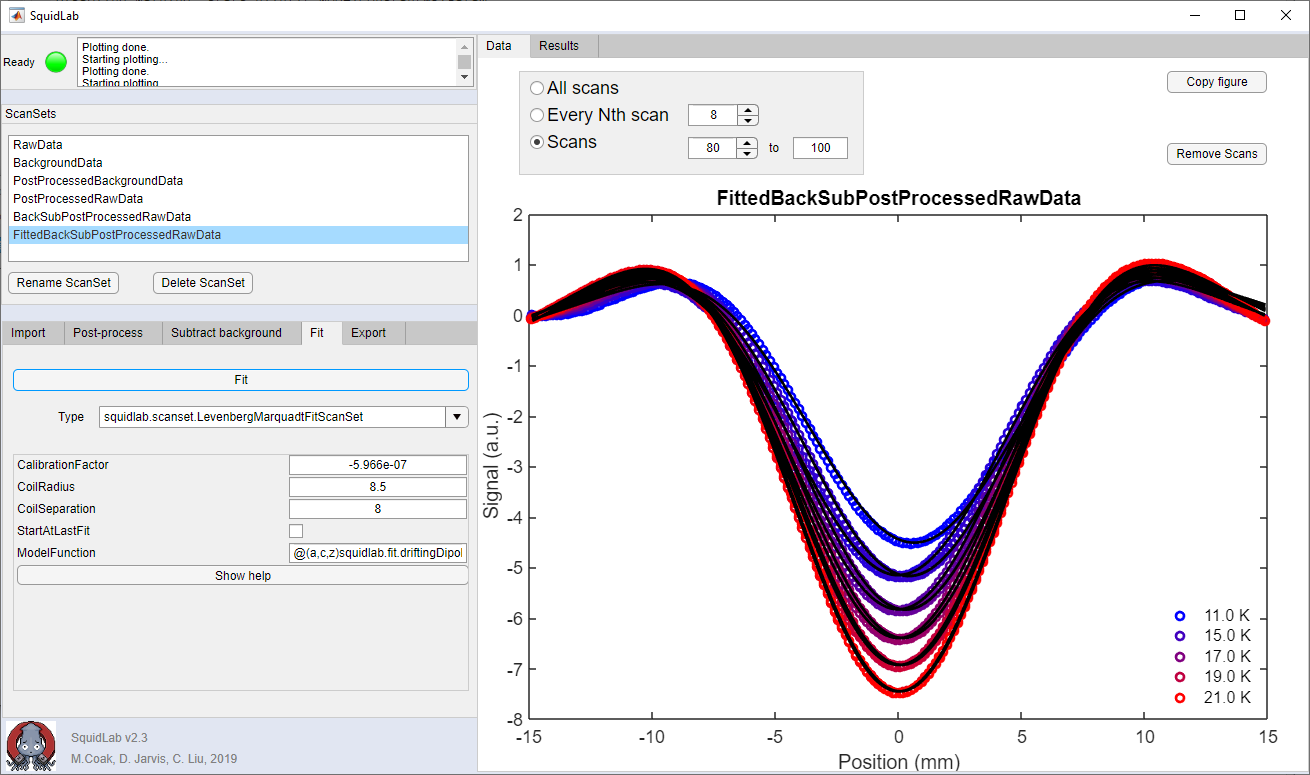

And if we check the Results tab in the top centre, we will see that a Moment vs Temperature plot has been extracted from these fits:

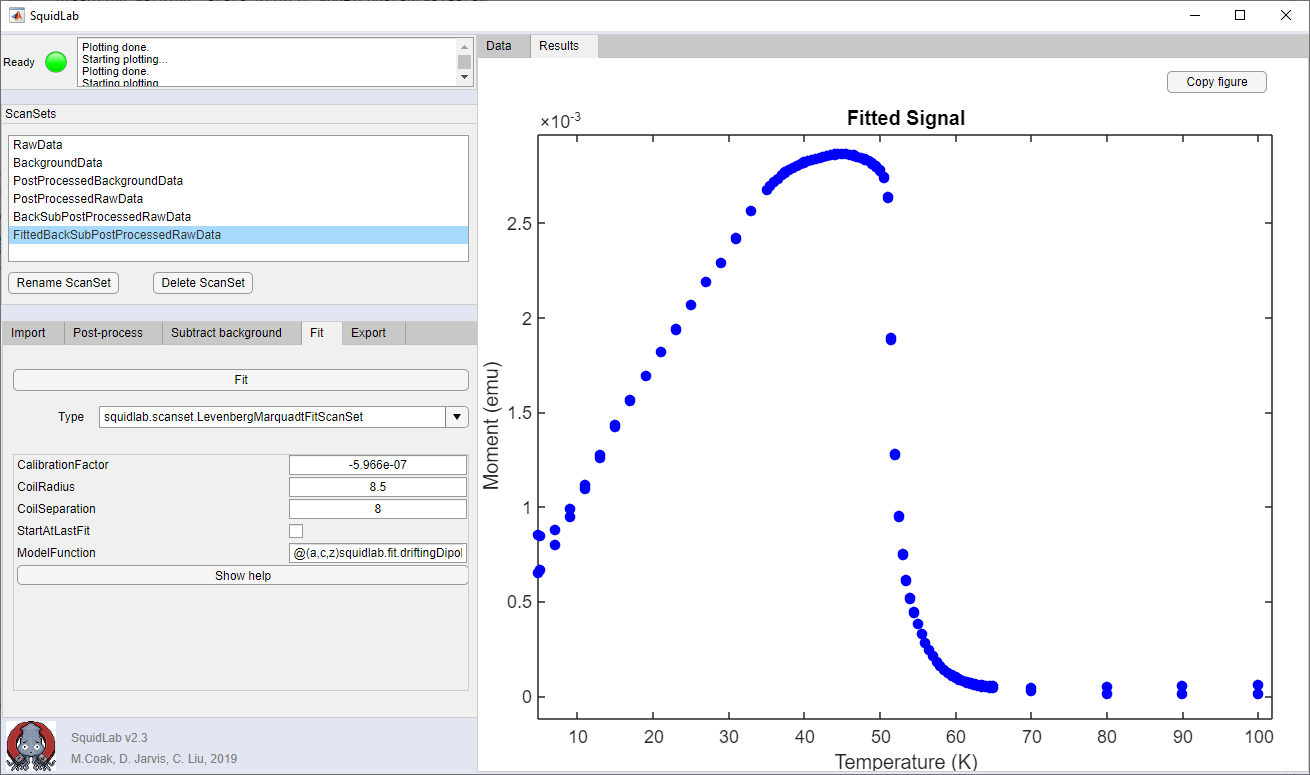

In this particular case, the background was very small (this is a ferromagnetic sample), and so this should look exactly the same as the .dat file the MPMS3 produced in the initial measurement. Indeed it does and so we are happy that all calibration factors etc are in order and the process has been a success.

#### 7 - Export the results

The Export tab looks like this:

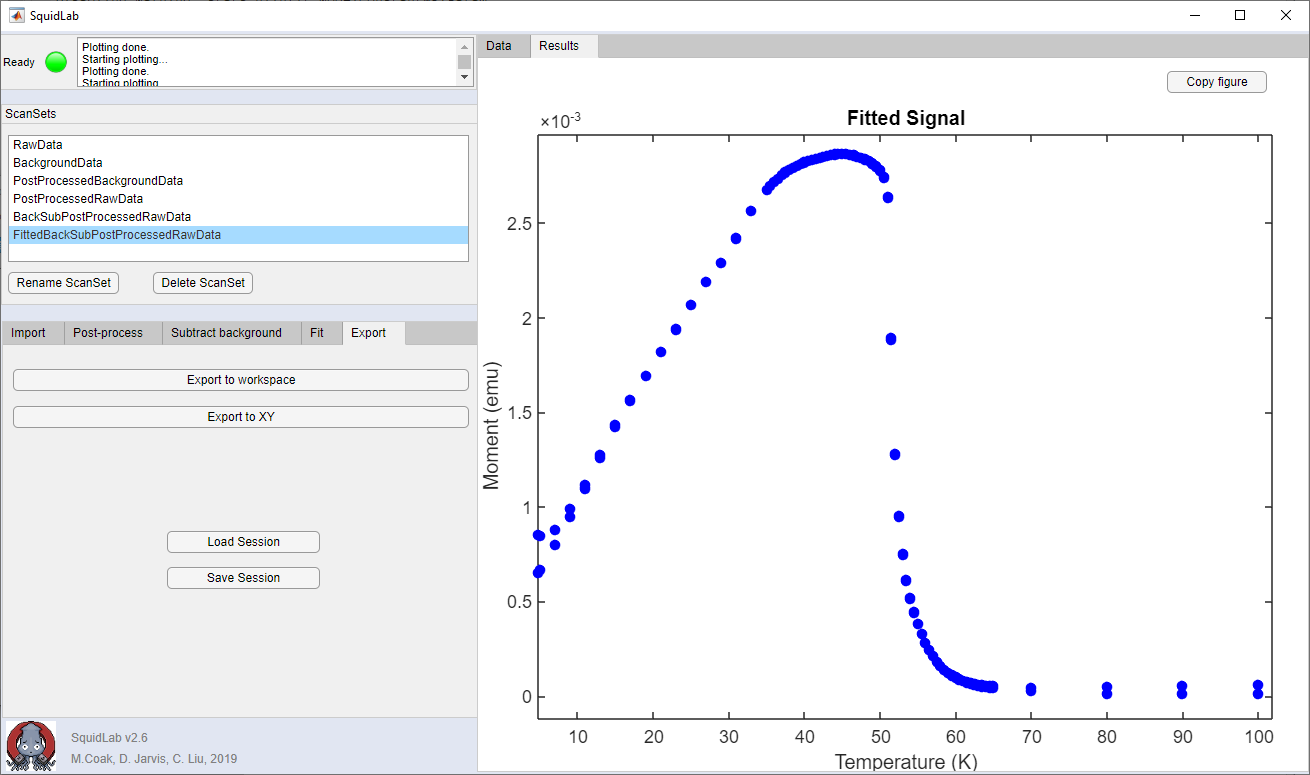

If you have performed a Fit, and hence the Results Axes have a graph like this in them, you can hit Export to XY to allow you to save a 2-column text file of these data to a destination of your choosing. 

Pressing Export to Workspace will dump all the existing ScanSets into the Matlab workspace - so everything is saved. Right click these and hit 'save as' in the Variables window and you will have stored all the data and parameters for future, advanced, analysis. ScanSets are pretty complex beasts! So Export to Workspace will also helpfully create a struct called Results with the Fitted Signal data stored in it as x and y. Note that you can of course use the command line tools on these ScanSet objects you just exported...

New to version 2.6 is the ability to save all your hard work and load it at a later date. The Load Session and Save Session buttons on the Export tab will save all the current ScanSets in the list into a Matlab .mat file (which you could easily open within Matlab too) for later use, and load that saved file to get back to where you were in that session. Note that Loading a Session will of course overwrite the currently open Session.

### Included Import Plugins

The following plugins are bundled with SquidLab, for importing data from the instruments/software versions we have encountered. Please feel free to contact us with requests for more, or to share new plugins or solutions you may have developed!

You will need a different plugin depending on whether your data are 'MvH' - Magnetic Moment as a function of Magnetic Field, at a fixed temperature, or 'MvT' (not actually written in the plugin name, this was assumed the default option) - Magnetic Moment as a function of Temperature, in a fixed field. Your datafiles should be split up into individual MvH and MvT sweeps, don't mix them! You may be able to cut and paste bits out of the raw data files to edit them in Notepad or equivalent if so.

The following are all options for MPMS3 datafiles. Different software versions or newer/older machines have slightly different data formats - trial and error will quickly find you the one to use to suit your instrument. MPMS3_Fast is a more heavily optimised, and faster Importer than MPMS3. The _MvH files are Moment vs Field alternatives to their equivalently named plugins.

- MPMS3_Alt

- MPMS3_Fast 

- MPMS3_MvH

- MPMS3_MvH_Alt

- MPMS3

These two are for the MPMS IQuantum 3-He system, which has different file formats (note they also have different file extensions):

- MPMS_IQuantum

- MPMS_IQuantum_MvH

And these two options are for the old generation MPMS systems (ie not MPMS3):

- MPMSXL

- MPMSXL_MvH

Additionally, the use of the MPMS Reciprocating Sample Option (RSO) is now supported (from v2.8) with these two plugins:

- MPMSXL_RSO

- MPMSXL_RSO_MvH

These RSO plugins are currently experimental, and we encourage feedback to test them and support their development. As RSO measurements sweep up and down for a single scan, and are very sensitive to perturbation, steady SQUID voltage drifts over time lead to the up and down scans not matching, and hence multi-valued voltage points as a function of z. As z values are not exactly reproduced, and the scans often do not start and end at the same position, removing this drift is surprisingly complex. A simplistic algorithm for drift removal is currently implemented in these two plugins  (`function VOut = SubtractVoltageDrift(~, V)` ), which the experienced user is encouraged to modify, improve or replace. We would love to hear of any improvements users develop, and are happy to offer assistance and explanation.

Finally, we also include importers for the S700X magnetometer from Cryogenic Inc:

The S700X outputs non-human-readable binary files (.dat and .wat, we use only the .dat). 

These first two plugins are for files that have been exported using the Labview Utility `Export Scans To Spreadsheet.vi` in library `sx-util.llb `supplied by Cryogenic. Note that the code assumes the user has not added any header lines to the datafile.

- S700X

- S700X_MvH

And these two are for the 'raw' .dat file straight from the instrument:

- S700X_Raw

- S700X_Raw_MvH

*Notes on the S700X importers - There will be a user-specified number of scans, stored as N columns in the data file. The importer simply averages these all together into a single column. Scans are assumed to be from eg -2cm -> max -> -2cm; the scans are split out of the raw file by looking for when Position returns to its starting value. Scans are additionally split into Up and Down on Import. Highly reccommended to use the AverageConsecutive option in PostProcessing. We specify eg a default coil separation of 4.1 mm following our tests - the Cryogenic fitting software uses 7.0, but fits it as a free parameter. You should investigate the optimal parameters and calibration factor for your system.*

As there are a huge variety of systems out there, which we could never completely test for, we recommend verifying that the raw data imported match those displayed in eg the MPMS's Multivu software, in shape and magnitude, the first time you use a plugin, to verify the data are parsed correctly.

### Example data analysis using the GUI

There are two sets of data - raw data and background for both MvH and MvT - included in the Example Data folder bundled into the SquidLab install directory:

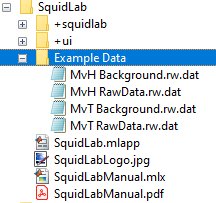

These are MvH (moment against magnetic field at set temperature) and MvT (moment against temperature at fixed field) scans for a diamagnetic sample on diamagnetic and paramagnetic sample holder, in an MPMS3. It is a nice idea to process and fit these data in the SquidLab GUI to verify your installation is working correctly and as training on the software's features.

For the MvT scan:

- Import 'MvT RawData.rw.dat' as outlined in the previous sections. No offset is neccessary. The importer to use for this file is 'MPMS3' (or 'MPMS3_Fast').

- You will get a warning about the SquidRange:

                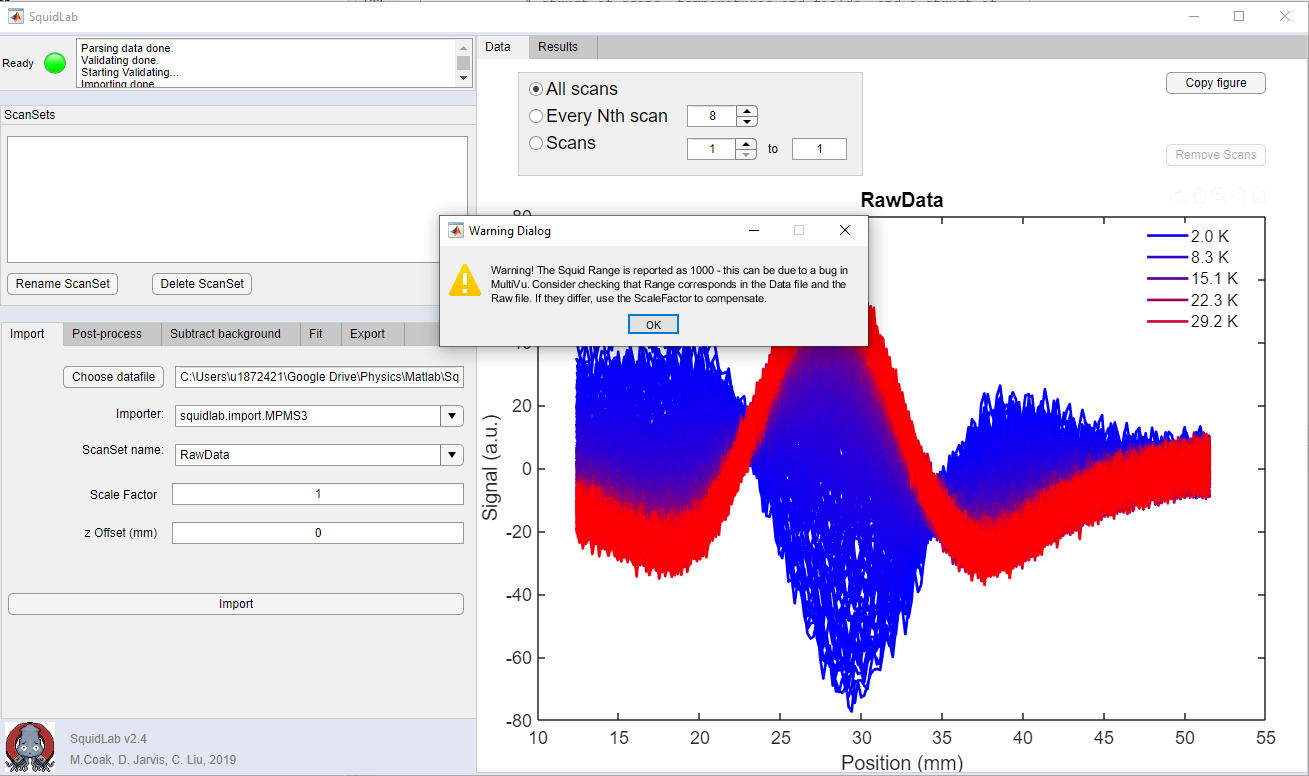

            .. this is expected - the MPMS3 this was measured on has the software version where this bug shows up. The non-raw .dat file is not included in the examples, but if one were to consult it, one would find SquidRange reported as 1, not 1000. This means our resulting moment is going to be 1000 times too large. We will carry on like this, but we could have set Scale Factor to 0.001 before hitting import to correct for this. Note - in v2.5 we now have a tickbox 'Get scale factor / SQUID Range from .dat file in the Advanced Import pane, which will handle this for you. 

If I open up (drag and drop into the workspace window) the .dat (not the .rw.dat) file in Matlab, I will see:

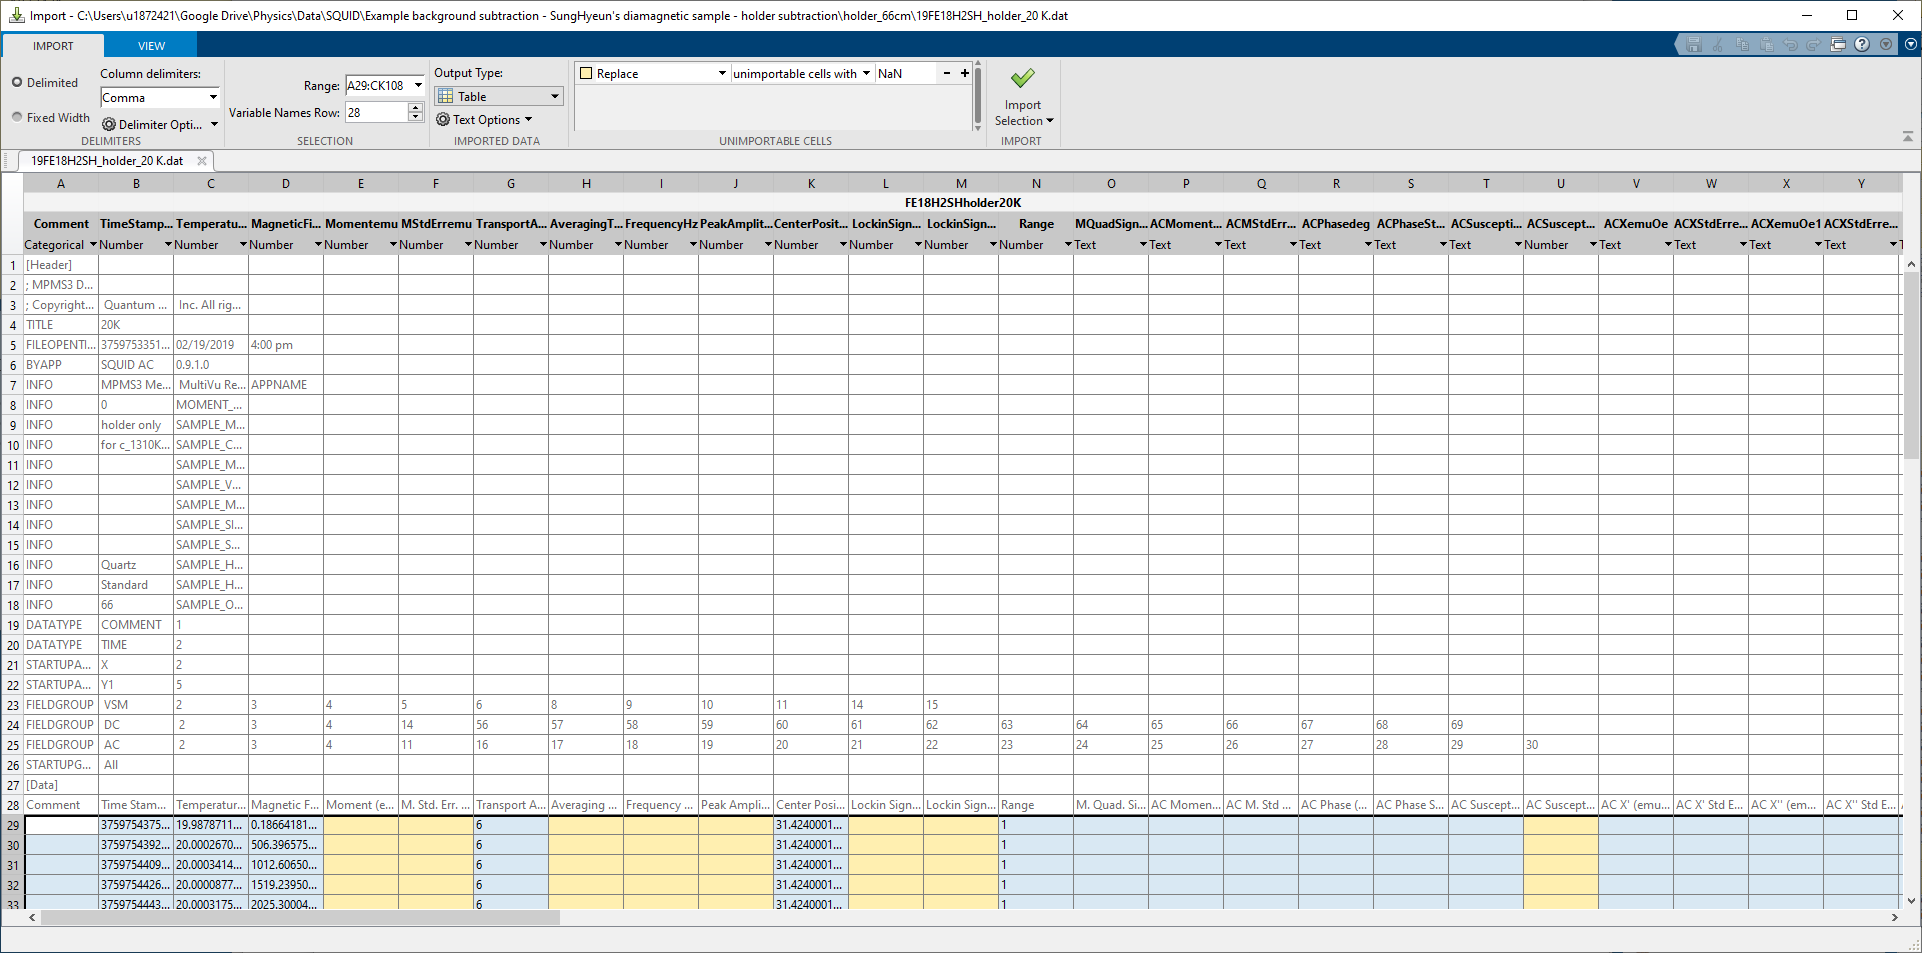

... There is a 'Range' column, whose value is 1 for each temperature point. And yet the .rw.dat file has, in the header line for each scan,

- so we need to divide by 1000 to get it right (the .dat is always right). Note that we can instead check the helpful box on the Import Advanced tab to have SquidLab load the .dat and extract the values for us.

- Import the corresponding background 'MvT Background.rw.dat' with the same options.

- PostProcess both in turn. These data look pretty noisy - so I turned SmoothingSpan up to 11. Weird duplicated results the first time made me then try ticking AverageConsecutive - and this indeed turns out to be a good idea for these datasets. Keep all default PostProcess arguments, except tick AverageConsecutive and increase SmoothingSpan to 11.

- At this point it should be pretty clear that the Background scans have an anomalous scan - a change in range or jump:

                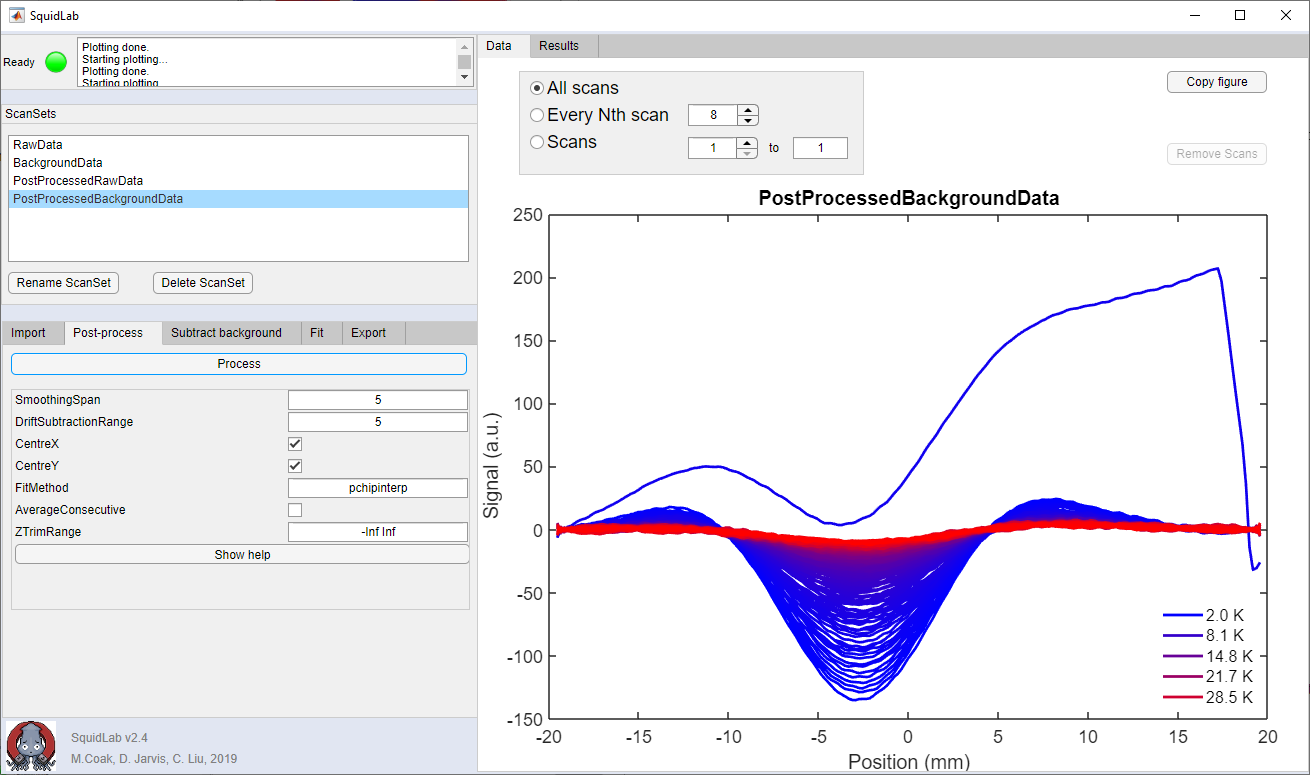

            This would cause some anomalous points around that temperature in the final result... or we could remove this scan. Select Scans as the plotting mode, rather than All scans, then plot only scan 15 by entering 15 and 15 in the numeric entry boxes to the right of 'Scans' and hitting enter. This is the bad one - it's clear to see when you find it:

                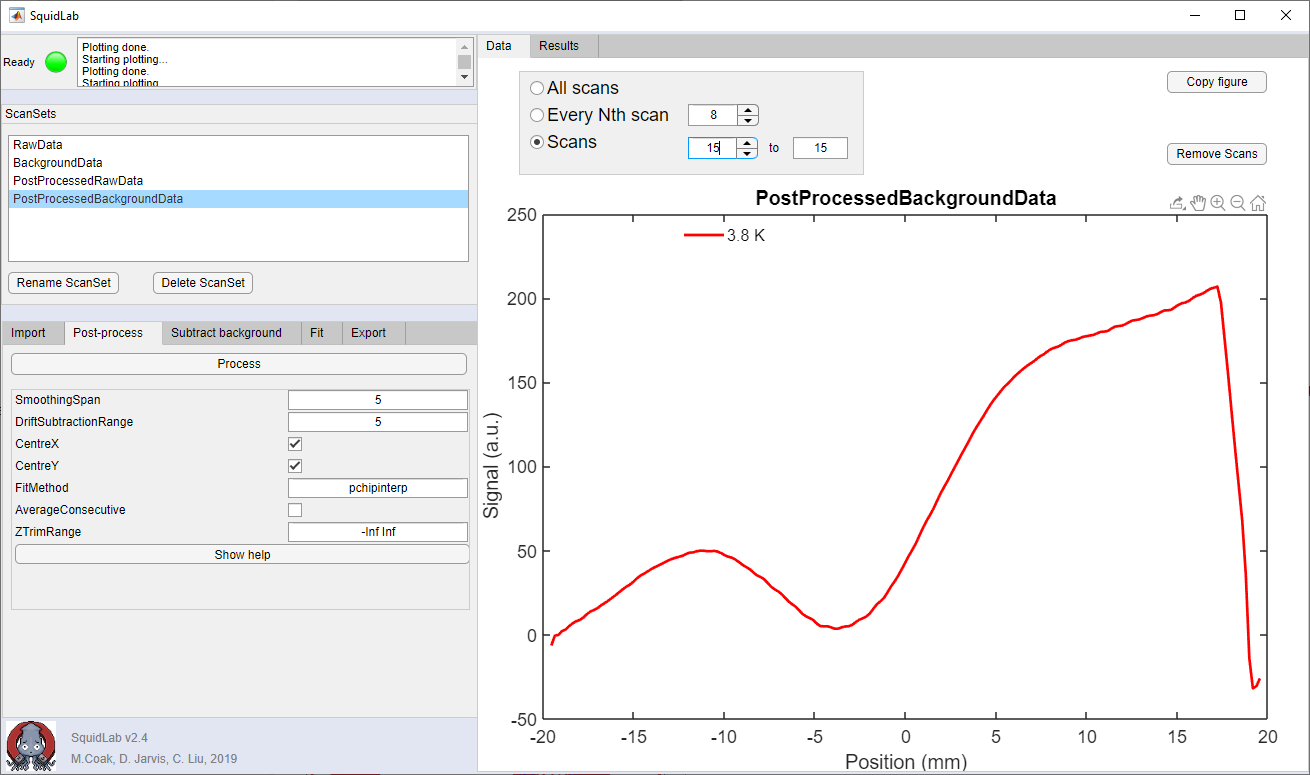

            Hit 'Remove Scans' and it should be deleted. Plotting All scans again should now look well behaved with the anomaly removed. NOTE - I removed this AFTER post-processing in this case, explicitly because I had to average two scans together in this step. I would have had to delete scans 29 AND 30 if I did it straight after import, or I'd have an odd number and AverageConsecutive would throw errors.

- Subtract background with default arguments. Should look like this:

                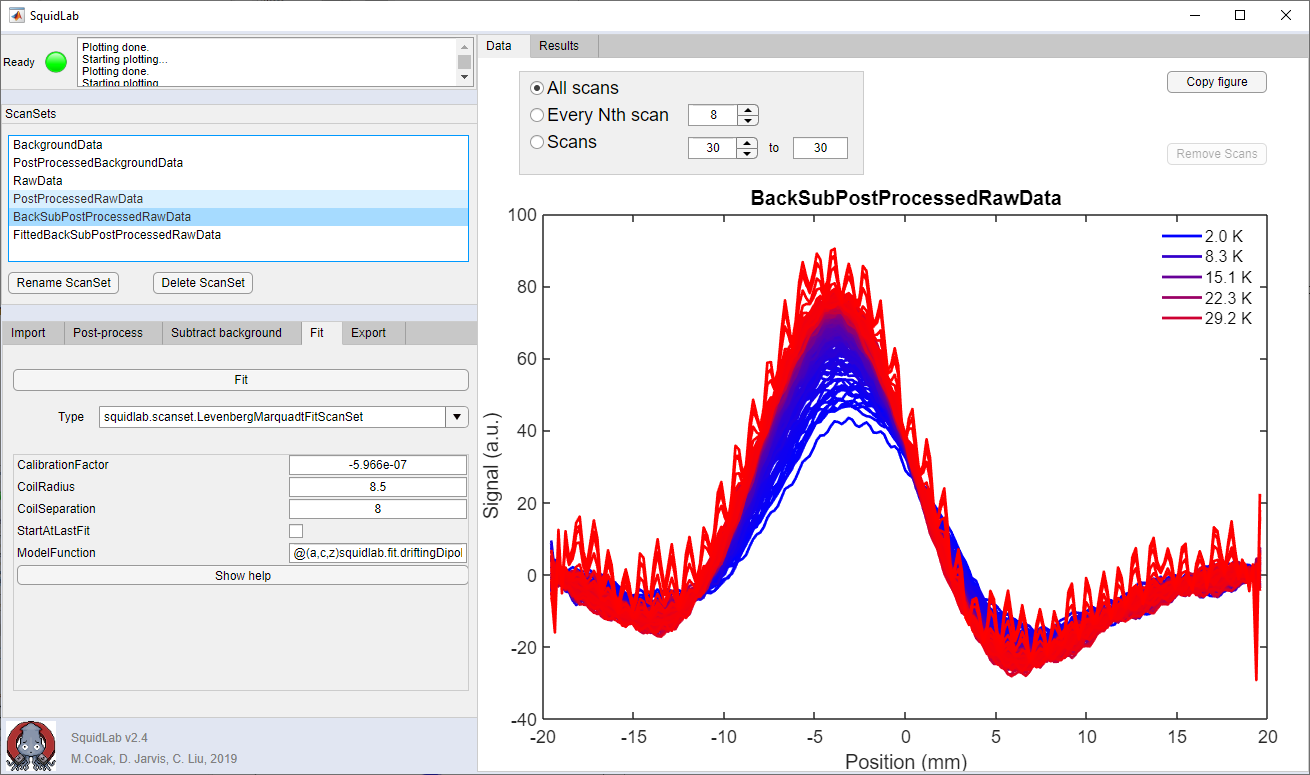

                looks pretty noisy - and also the dipole isn't quite centred. One could run another PostProcess step now, smooth it out, z-trim -20 to 15, CentreX again, to get it smooth and centred, but in this case it seems to fit just fine.

- Levenberg-Marquadt fit with the default parameters gives a lovely fit to the clear dipole there, even though it's off centre..

And I end up with this final result, which hopefully you will also see if you followed these steps:

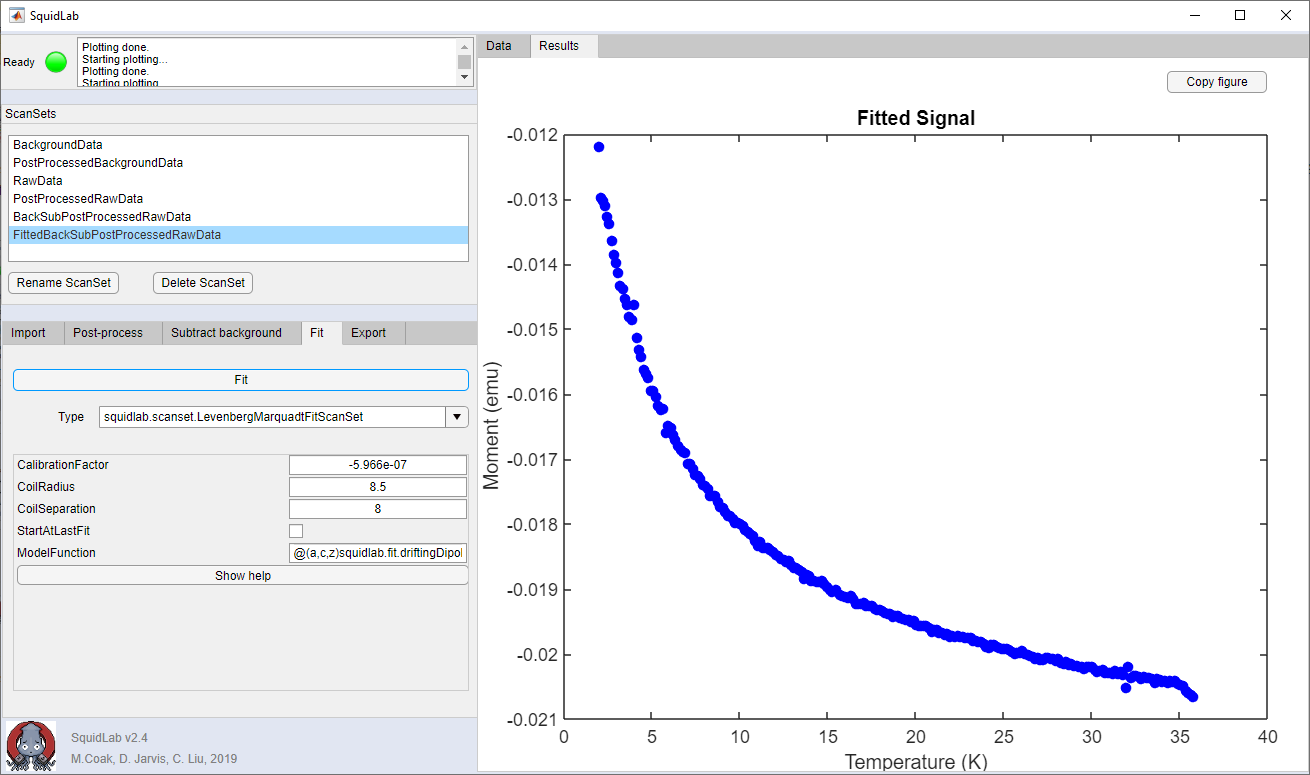

Again - because I didn't correct for the SquidRange issue, I have a moment 1000 times bigger than it really should be! 

Following the same steps, same parameters for the MvH files gives me this result:

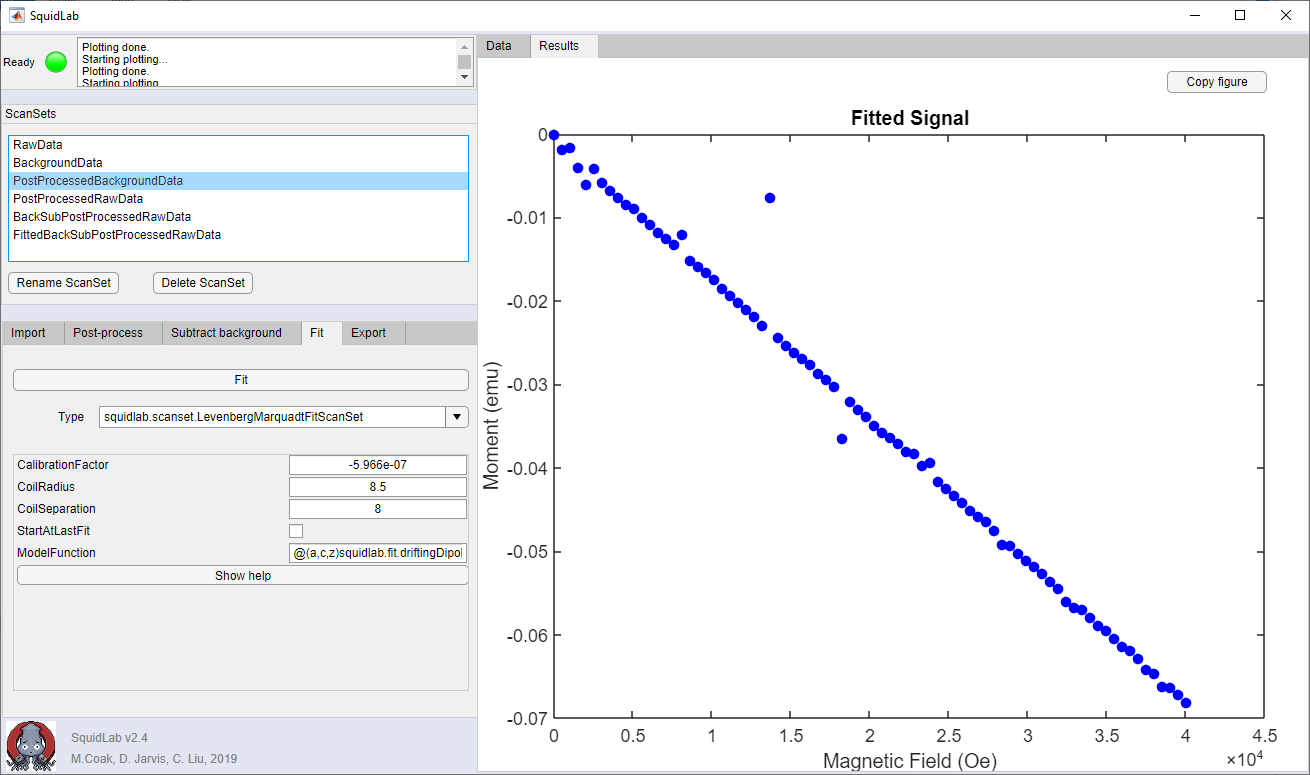

There are a few anomalous points, which were clear in the scans upon import. These could be removed after Postprocessing, as with the MvT. Also has the SquidRange 1000 issue!

A final point - Version 2.7 added these colourful buttons:

and the Custom Plot tab to the right of the Results Tab.

This allows quick and easy comparison of 2 data sets, particularly in the case where we need to work out a z-offset to apply. It works best if used when displaying only a single curve:

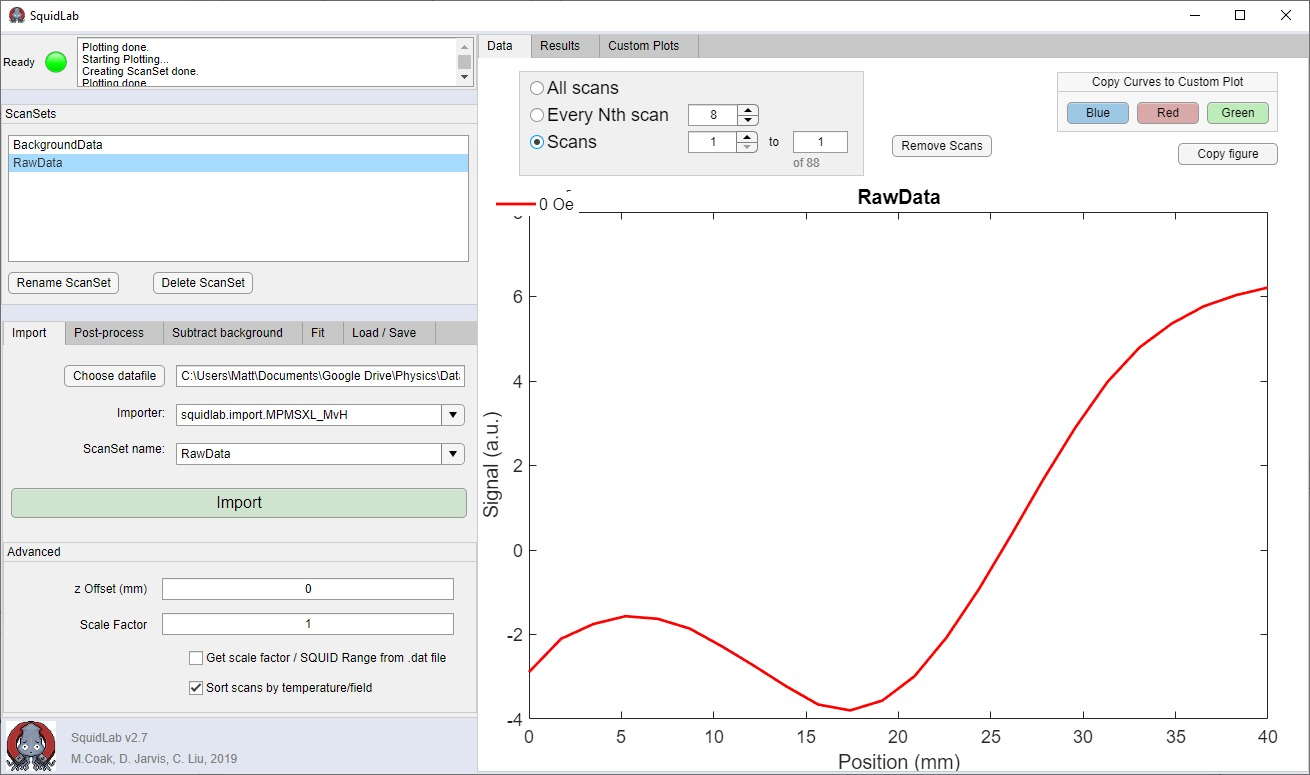

If I hit the 'Blue' button while displaying this curve, then select the BackgroundData ScanSet in the top-left list and then hit 'Red'. I will get:

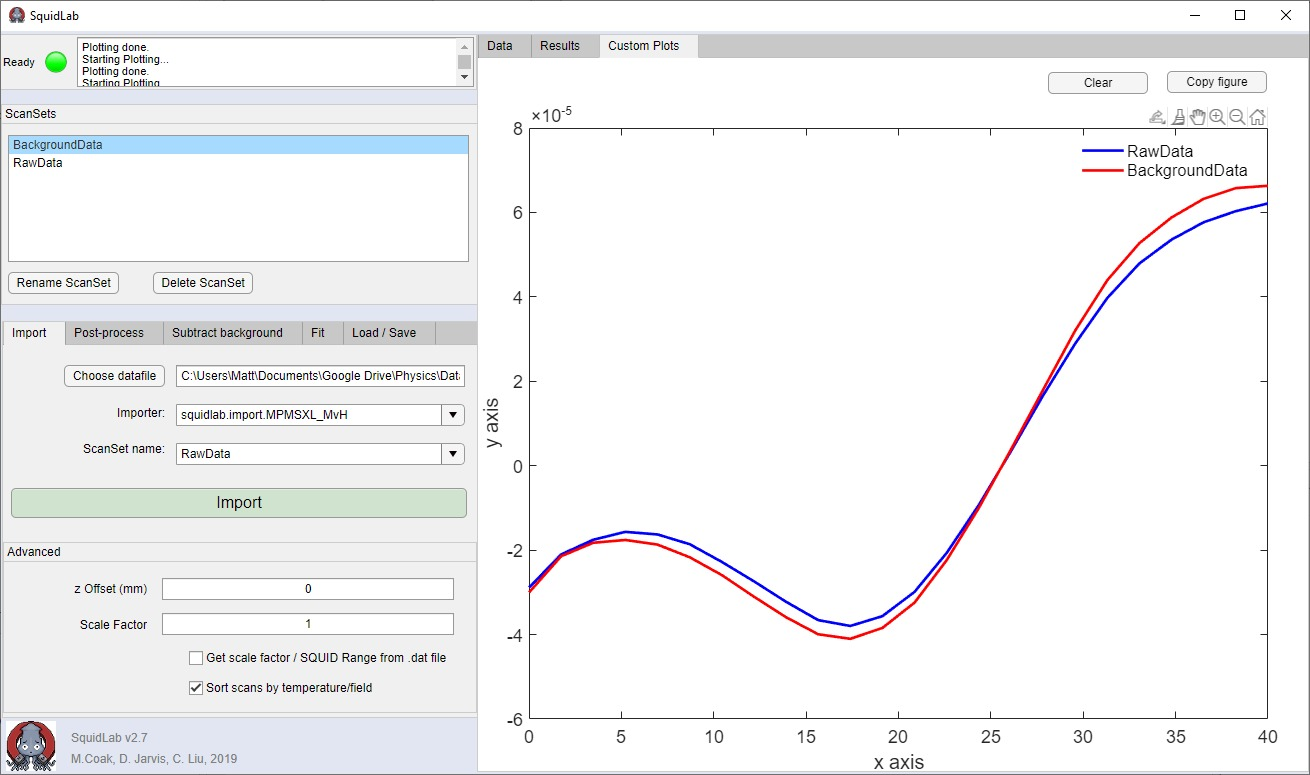

Curves will keep getting added to the existing ones on this tab - you can hit 'Clear' to remove all displayed plots on these axes. And of course 'Copy Figure' to save your beautiful comparison plots for later.

### To sum up..

These steps should have got you through a full analysis and background subtraction of magnetic data using SquidLab. 

`You can safely stop reading now! `

The rest of the manual will deal with more advanced topics than are needed to pick up SquidLab and use it for 99% of tasks. Thanks for reading this far! Again do get in touch with questions, issues, suggestions.

## Creating new plugins

Understanding this section will require a working knowledge of object-oriented programming and concepts of class heirachy and abstract methods and properties. Explaining all this is... beyond the scope of this manual! Quite possibly however one could make a new plugin by copy-pasting an existing one and modifying the important bits, without really 100% understanding what was going on! 

On startup, SquidLab will look for all non-Abstract classes in the +import folder which inherit from the Abstract class 'squidlab.import.ImportPipeline'. You can find this class - and hence the information on what methods and properties must be implemented in the child class in this same folder. The class LineReadingImportPipeline, which MPMS3 Importers inherit from, inherits from ImportPipeline, and gives several helpful shared methods for these cases. These are for data files where we must go through each line one-by-one and parse it, then split blocks of these lines into single scans - the MPMS file are much simpler and can be imported into a single 2D array which we can then chop up into individual scans with full predictability.

Here is the Importer class MPMSXL.m, which you will find in the +import folder of your SquidLab install (We have removed the actual code in process() because it's really long and doesn't help us in this discussion. See the .m file itself for the unedited code and hence the contents of this function in reailty): 

classdef MPMSXL < squidlab.import.ImportPipeline
    %Import pipeline for an old generation MPMS XL datafile, which doesnt
    %have headed blocks of data throught the raw file, but instead a single
    %table of values. Trick is to find out how many points are in a scan,
    %then chop the data into chunks based on that.
    
    properties
        HeaderLines = 31; % We want to ignore this many lines of the file as header.
        RescaleFactor = 1;
    end
    
    methods (Access = protected)
        function [meta] = GetMetaData(this)
            meta.XVar = 'T';
            meta.CalibrationFactor = 1.096e-3;
            meta.CoilRadius = 9.7;
            meta.CoilSeparation = 15.19;
            meta.CryostatInfo = 'MPMS or MPMSXL, standard format, MvT';
        end
    end
    
    methods(Access = public)

        function [results, info] = process(this, fileName, scaleFactor)
            %Tell the logger we are busy importing
            this.Logger.setBusy("import");            
            
            % Allocate a 3D array to store data. This array will
            % eventually be [NumDataPointsPerScan x 2 x NumScans].
            % For every scan, there are NumDataPointsPerScan [position,
            % signal] pairs.
            scanData = nan(pointsInFirstScan,2,numberOfScans);
            
            %Some really long and complex import commands that we don't 
            %really need to print here - look at the code file if interested
            
            % Results to return.
            results.Temperatures = temperatures;
            results.Fields = fields;
            results.ScanData = scanData;
            
            % Diagnostics to return.
            info.FileName = fileName;
            info.NumScans = numberOfScans;
            info.TimeInSeconds = toc(timer);
            info.Meta = this.GetMetaData();
            
            %Tell the Logger we finished
            this.Logger.setFinished("Import");
        end
    end
    
    methods(Access = protected)
        
        function pointsInScan = getNumberOfPointsInScan(~, positionsArray)
            %Position values in a single scan ramp up continuously, then
            %reset to zero for the next. Look at data and see where they
            %stop increasing - that's the start of a new scan
            deltaP = 1;
            n = 1;
            while(deltaP > 0)
                deltaP = positionsArray(n+1) - positionsArray(n);
                n = n +1;
            end
            pointsInScan = n-1;
        end       
        
    end
    
end

Firstly, take note of what form the data must end up in:

% Allocate a 3D array to store data. This array will
% eventually be [NumDataPointsPerScan x 2 x NumScans].
% For every scan, there are NumDataPointsPerScan [position,
% signal] pairs.
scanData = nan(pointsInFirstScan,2,numberOfScans);

... a 3D array of voltages and positions (hence the dimension of 2). There will be `pointsInFirstScan` voltages and corresponding positions in each Scan, and `numberOfScans `scans, all stacked into a single array. For debugging, you can Export to Workspace a previously imported ScanSet and take a look at its ScanData property. Or insert some Breakpoints into an existing importer and inspect the contents of a scanData local variable.

Slightly ugly note! SquidLab always thinks its independent variable is Temperature, even if this is an MvH sweep... MvH was added late in development and the terminology never changed. Therefore, you may find things like this in MvH importers:

%Retrieve temperature and field data for this scan - note
%the awful hack, switching 'fields' and 'temperatures'
fields(i) = mean([dataTable.StartTemperatureK((i-1)* pointsInFirstScan+1), dataTable.EndTemperatureK(i* pointsInFirstScan)]);
temperatures(i) = dataTable.FieldOe((i-1)* pointsInFirstScan+1);

... `Results.Temperatures` ends up being a list of Fields, and `Fields` is a list of temperatures! It is not a typo in the code, but yes it is a bit ugly. The metadata

meta.XVar = 'T';

which the Importer returns to SquidLab will inform the plotting tools whether we have 'T' or 'H' as our 'x axis' so it can label it appropriately. There's actually no difference under the hood!

The `GetMetaData` function is made here to return the metadata struct that SquidLab will inspect to autopopulate things like the fitting parameters. Copy this function wholesale, and simply edit the values assigned if making new Importers.

The class definition is:

classdef MPMSXL < squidlab.import.ImportPipeline    

- note that the filename it is saved as must match this name (MPMSXL.m). '<' means 'inherits from' and then ImportPipeline is of course the class this one inherits from. If all these things aren't right, this entry will not appear in the drop-downs in the SquidLab GUI. 

A final hint for any such work modifying SquidLab...

    classdef UILogger < squidlab.utils.Logger
    % UILogger  Logger intended to be embedded in uifigure.
    %
    % Example:
    %   u = uifigure();
    %   pos = [0 0 300 300];
    %   logger = UILogger(u, pos);
    %   logger.logInfo("Some message");
    %   logger.setBusy("starting");
    %   logger.setFinished("done");
    
    properties (Access=public)
       DebugMode = true;   %Set to true to rethrow all handled errors and hence have a stack trace to follow in the command window - for debugging/testing purposes 
    end

... set `DebugMode` to true in `+squidlab/+utils/UILogger.m` and you will get errors sent to the command window. This will let you more clearly follow stack traces and track down problems and debug.

## Using the command line tools

The GUI provides a convenient wrapper around the underlying Squidlab commands and code. Power users who wish to script, automate, or batch process data, or to more heavily modify their processing routines, alternatively have access to both a high-level and low-level API from the Matlab command window. 

Note that namespaces must be included! eg 'squidlab.Actions' not just 'Actions'.

### Example analysis with the Actions API

Navigate to the top-level SquidLab directory.  Ie your Matlab window should look like this (but with an Example Data folder in there too now!):

We'll use the example data in the cunningly named ExampleData file. Set the filepaths:

% Datafiles to import.
dataFilePath = "SquidLab/Example Data/MvT RawData.rw.dat";
backgroundFilePath = "SquidLab/Example Data/MvT Background.rw.dat";

Importing, processing and fitting the raw data requires creating an Actions object, which is a convenience wrapper for the low-level API.

actions = squidlab.Actions;

We do the data import using an importer specific to the MPMS3, which took the data.

% Do data import.
importerName = "squidlab.import.MPMS3";
scaleFactor = 1;

% The import is probably quite slow.
rawData = actions.importData(dataFilePath, importerName, scaleFactor);
rawBackground = actions.importData(backgroundFilePath, importerName, scaleFactor);


This loads the data from the two .dat files into structs `rawData` and `rawBackground`:

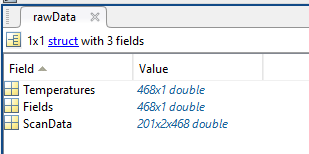

 To use the data in SquidLab, we want to convert this to a ScanSet. ScanSets of some variety are the backbone of SquidLab. We're going to want to do some post-processing on the data (e.g. to ensure it's centred in the z-direction), so we'll just directly create a PostProcessedScanSet.

ppData = actions.postProcess(rawData, 'AverageConsecutive', true, 'SmoothingSpan', 11);
ppBackground = actions.postProcess(rawBackground, 'AverageConsecutive', true, 'SmoothingSpan', 11);

Note that an optional number of arguments are allowed - we can jsut call `actions.postProcess(rawData); to use the default arguments. Here we use the same options as walked through in the GUI example.`

Let's take a look at our data.

ppData.plot();

The result should be a smoothed, centred SQUID scan.

Note that each command like this returns a ScanSet object, and wants to be given a ScanSet object, so you can chain these in any order as many times as desired.

We can adjust plotting options, eg:

ppData.Plotter.NewFigure = true;

Both background subtraction and fitting are also pretty easy.

backsubScanSet = actions.subtractBackground(ppData, ppBackground);
lmFittedScanSet = actions.fitLevenbergMarquadt(backsubScanSet);

We can straightforwardly visualize the results of the fits with a couple of commands.

% There's too many temperature scans, so the plot will look cluttered. 
% Show only every 10th scan.
lmFittedScanSet.UseEvery = 10;
lmFittedScanSet.plot();
lmFittedScanSet.plotFitResults();

Giving us:

### 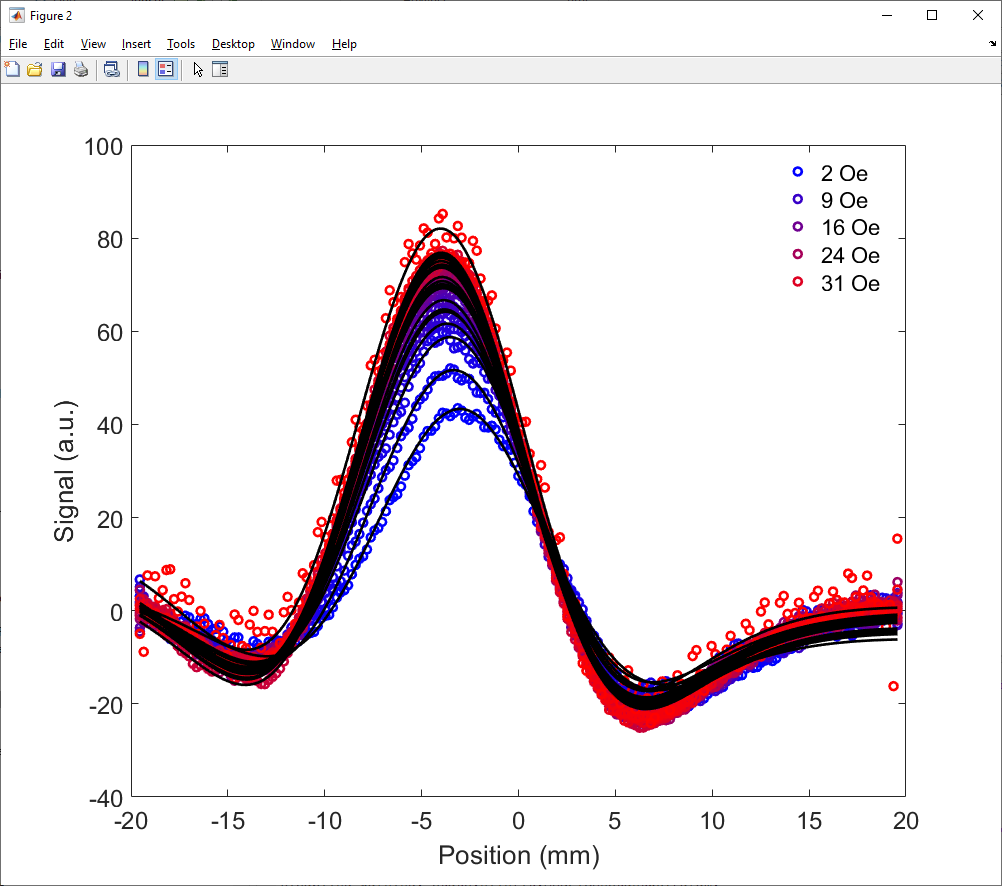

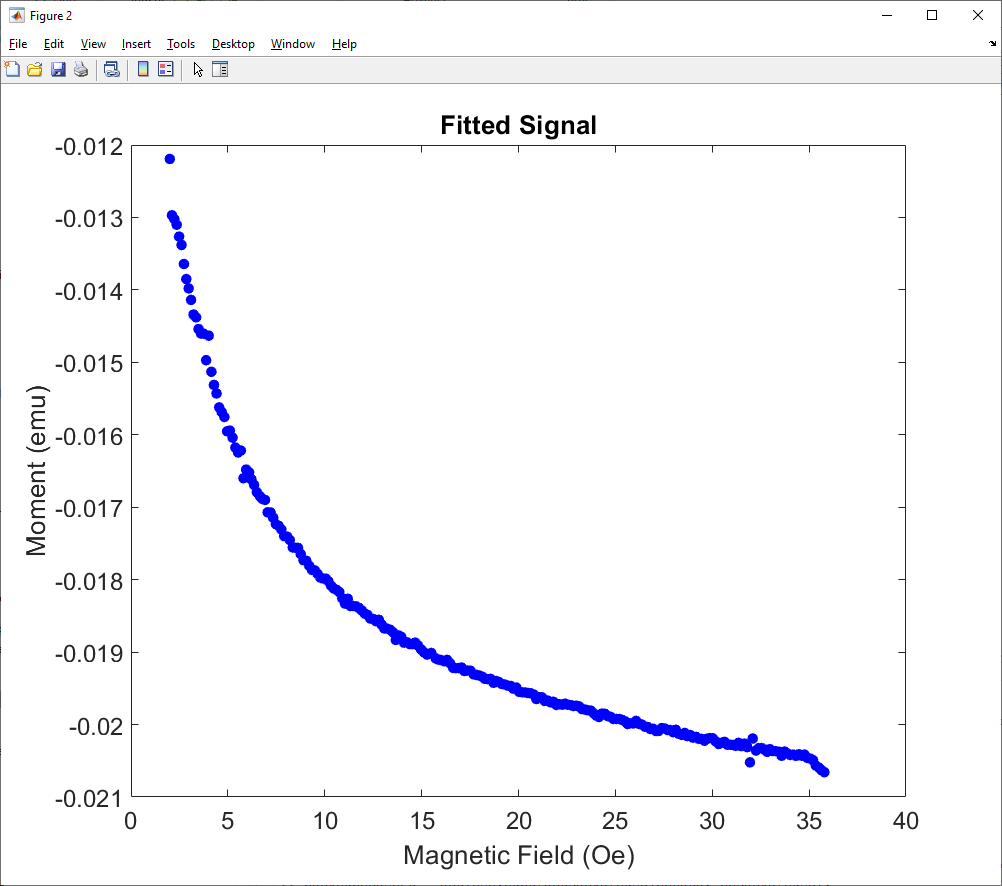

### Example analysis with the low-level API

You're probably wondering what the point is of exposing two command-line APIs, particularly in a language like Matlab where you can just read and modify the source code anyway. This is a pretty good question! Basically, the answer is that the Actions API is intended to provide a quick-to-use way to access 90% of the functionality, but isn't intended to be extensible for developers. In general, it's much less verbose and more user friendly, at the expense of providing places for you to inject your own modifications.

If you want to develop new functionality for SquidLab, you'll need to use the low-level API, which is designed to be easily extensible and modifiable. If you want to modify and extend it, you should have a good knowledge of Matlab OOP. The low-level API contains a large number of modular building blocks, which should be easily reusable in your own extensions.

To import data, we need an ImportPipeline. We'll make one for the MPMS3 - we only need one ImportPipeline, even though we have 2 datafiles, as they're both the same sort of file.

% Datafiles to import.
dataFilePath = "SquidLab/Example Data/MvT RawData.rw.dat";
backgroundFilePath = "SquidLab/Example Data/MvT Background.rw.dat";

%Create a Logger object, an import pipeline, and define some variables
logger = squidlab.utils.CommandLineLogger();
pipeline = squidlab.import.MPMS3();
scaleFactor = 1;

%Assign the logger to the pipeline
pipeline.Logger = logger;

% Import the data via the pipeline/Importer
[rawData, info] = pipeline.process(dataFilePath, scaleFactor);
[rawBackground, info] = pipeline.process(backgroundFilePath, scaleFactor);

We'll turn this raw data struct into, sequentially, a RawScanSet, a PostProcessedScanSet, and a BackgroundSubtractedScanSet.

% Create raw scansets.
rawDataScanSet = squidlab.scanset.RawScanSet(rawData.Temperatures, ...
    rawData.Fields, rawData.ScanData);
rawBackgroundScanSet = squidlab.scanset.RawScanSet(rawBackground.Temperatures, ...
    rawBackground.Fields, rawBackground.ScanData);

%Plot the data to have a look
rawDataScanSet.plot();

% Create post-processed ones and do post-processing.
% As an example, we'll change some properties here.
ppDataScanSet = squidlab.scanset.PostProcessedScanSet(rawDataScanSet);

% In this case, we won't fit the data with a spline, and use a smaller
% smoothing window. This will give less smooth results.
%
% Don't forget to actually call the postProcess method, to do the processing.
% You can set post-processing settings in advance on the object, or when 
% % postProcess is called.
ppDataScanSet.FitMethod = "none";
ppDataScanSet.postProcess('SmoothingSpan', 3);

% Same for the background.
ppBackgroundScanSet = squidlab.scanset.PostProcessedScanSet(rawBackgroundScanSet);
ppBackgroundScanSet.FitMethod = "none";
ppBackgroundScanSet.postProcess('SmoothingSpan', 3);

% Do background subtraction.
% We need to map the background scans onto the same temperatures as the 
% data scans.
%
% Interpolation on a 2D surface is (by far) the best way to do this, 
% but "nearest" is another option in case this interpolation makes you queasy.
interpMode = "interp";
backsubScanSet = squidlab.scanset.BackgroundSubtractedScanSet(...
    ppDataScanSet, ppBackgroundScanSet, interpMode);


Fitting the data is pretty much the same as before. Here, we'll fit with singular value decomposition, because why not?

svdScanSet = squidlab.scanset.SVDFitScanSet(backsubScanSet);

% Fourth-order multipole works best. Higher order multipole terms 
% suffer weird issues due to numeric instabilities. 
svdScanSet.MultipoleOrder = 4;
svdScanSet.fit(); 

% Plot the results.
svdScanSet.UseEvery = 10;
close all;
svdScanSet.plot();
svdScanSet.plotFitResults();

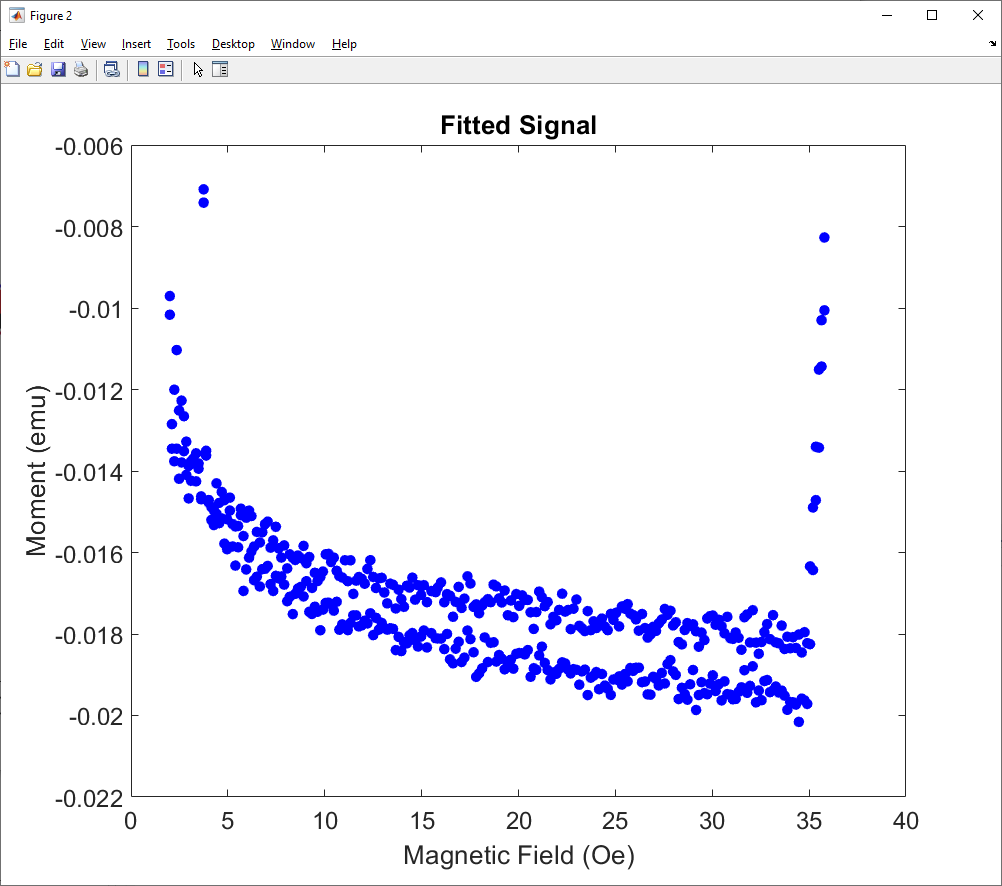

... and this is the result! It looks odd - multivalued - because we didn't set AverageConsecutive to be true when PostProcessing!

Though obviously less intuitive than using the GUI, these steps can be easily scripted, extended or modified. 